# Optics Figures - Figure 5,6

## Figure 5 - **Physiological optics**

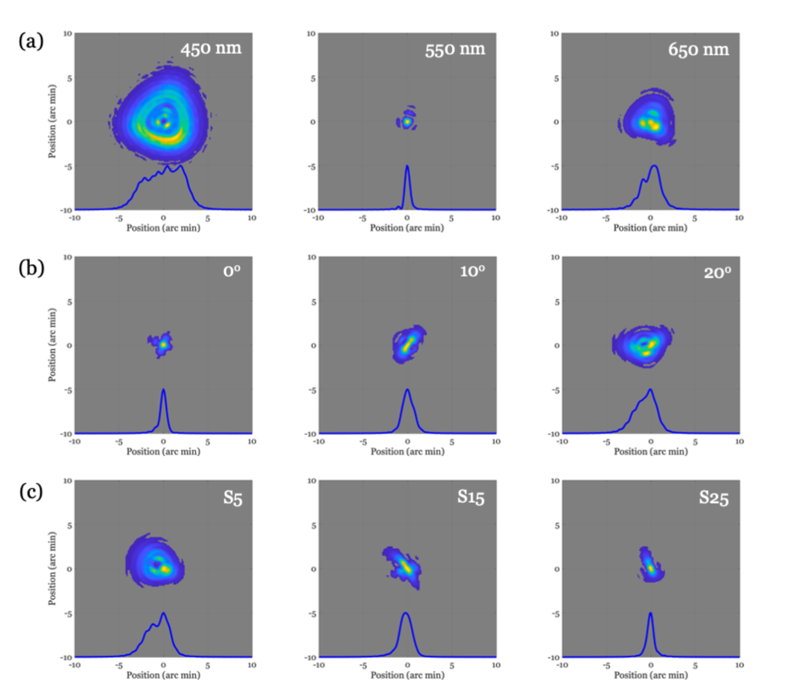

**Physiological optics.** The images represent the human point spread function (PSF), measured at different wavelengths and visual field positions. The blue lines are the corresponding vertical line spread function (LSF) computed by summing the PSF down the columns. (a) Comparisons at different wavelengths for subject 1 in the fovea. (b) Comparison at different eccentricities for subject 4 at 550 nm. (c) Comparisons of three subjects at 550 nm and 5◦ eccentricity. The PSFs and LSFs were calculated using ISETBio with data from [Jaeken and Artal, 2012].

zCoeffDatabase   = 'Artal2012';
eyeside          = 'right';
pupilDiamMM      = 3.0;
centerpsf        = true;
wave             = 400:10:700;

### Top row

Subject 49 from right eye requires central refraction correction


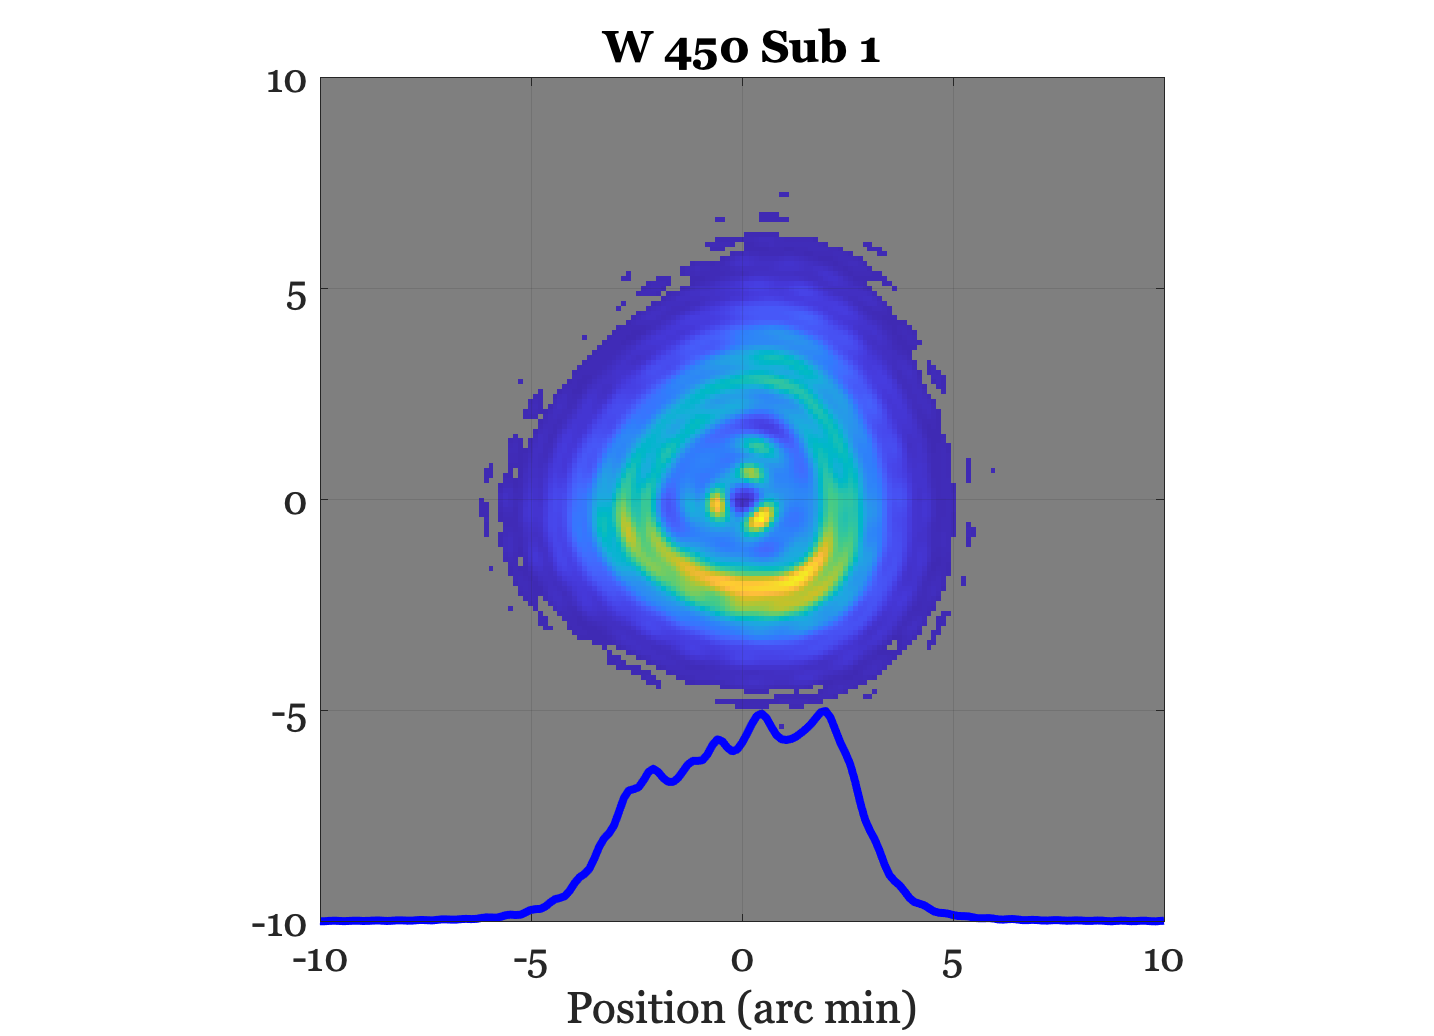

Subject 49 from right eye requires central refraction correction


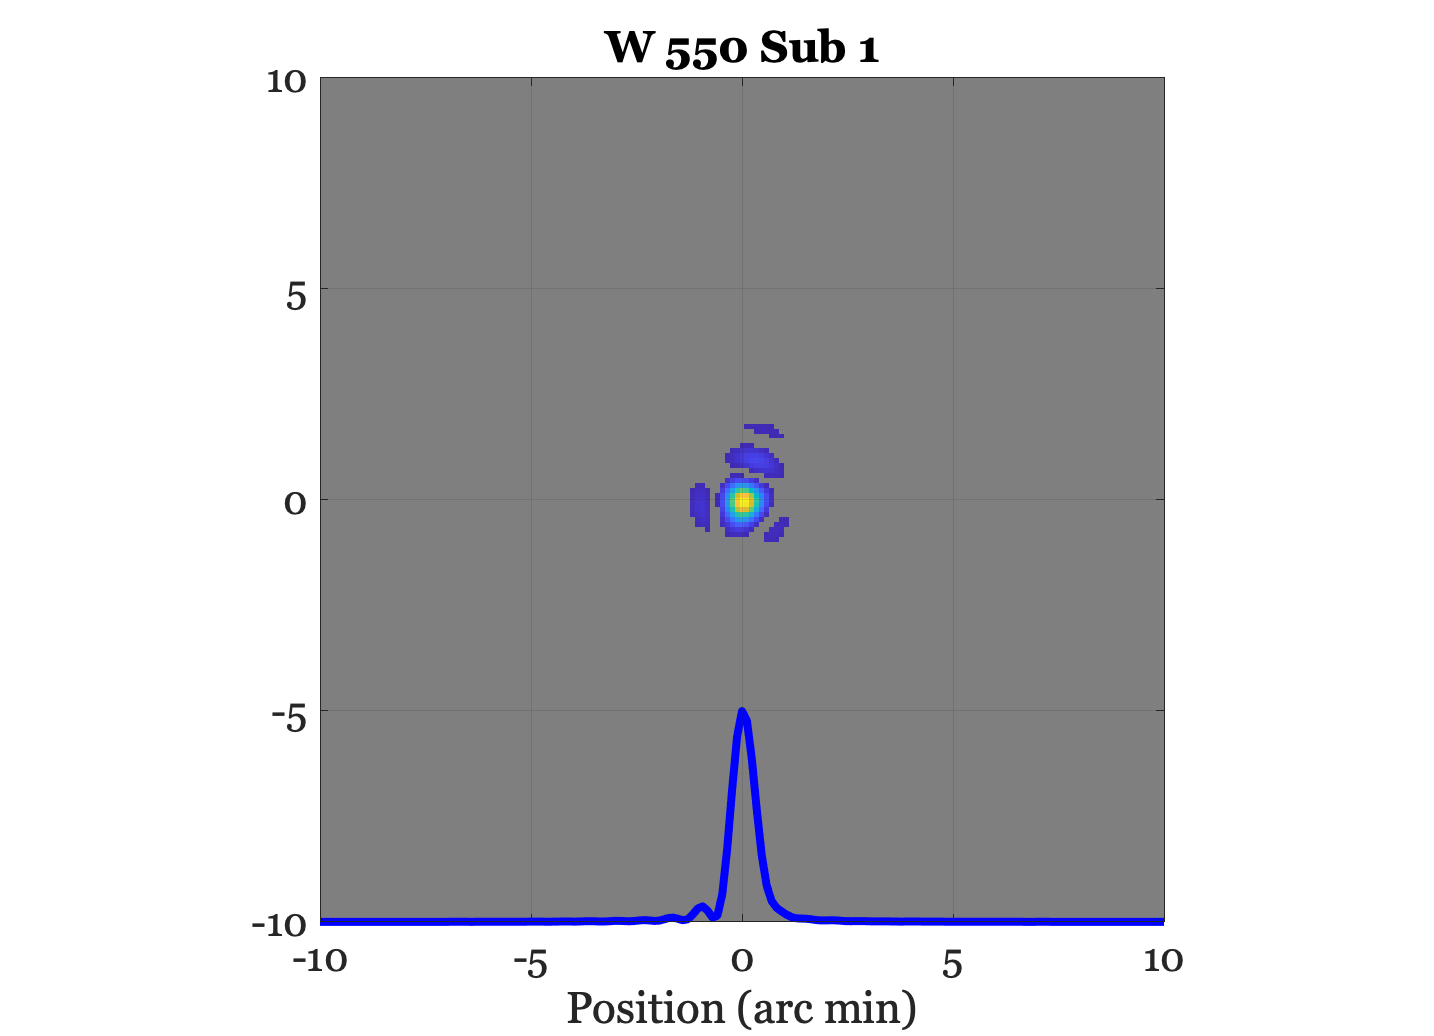

Subject 49 from right eye requires central refraction correction


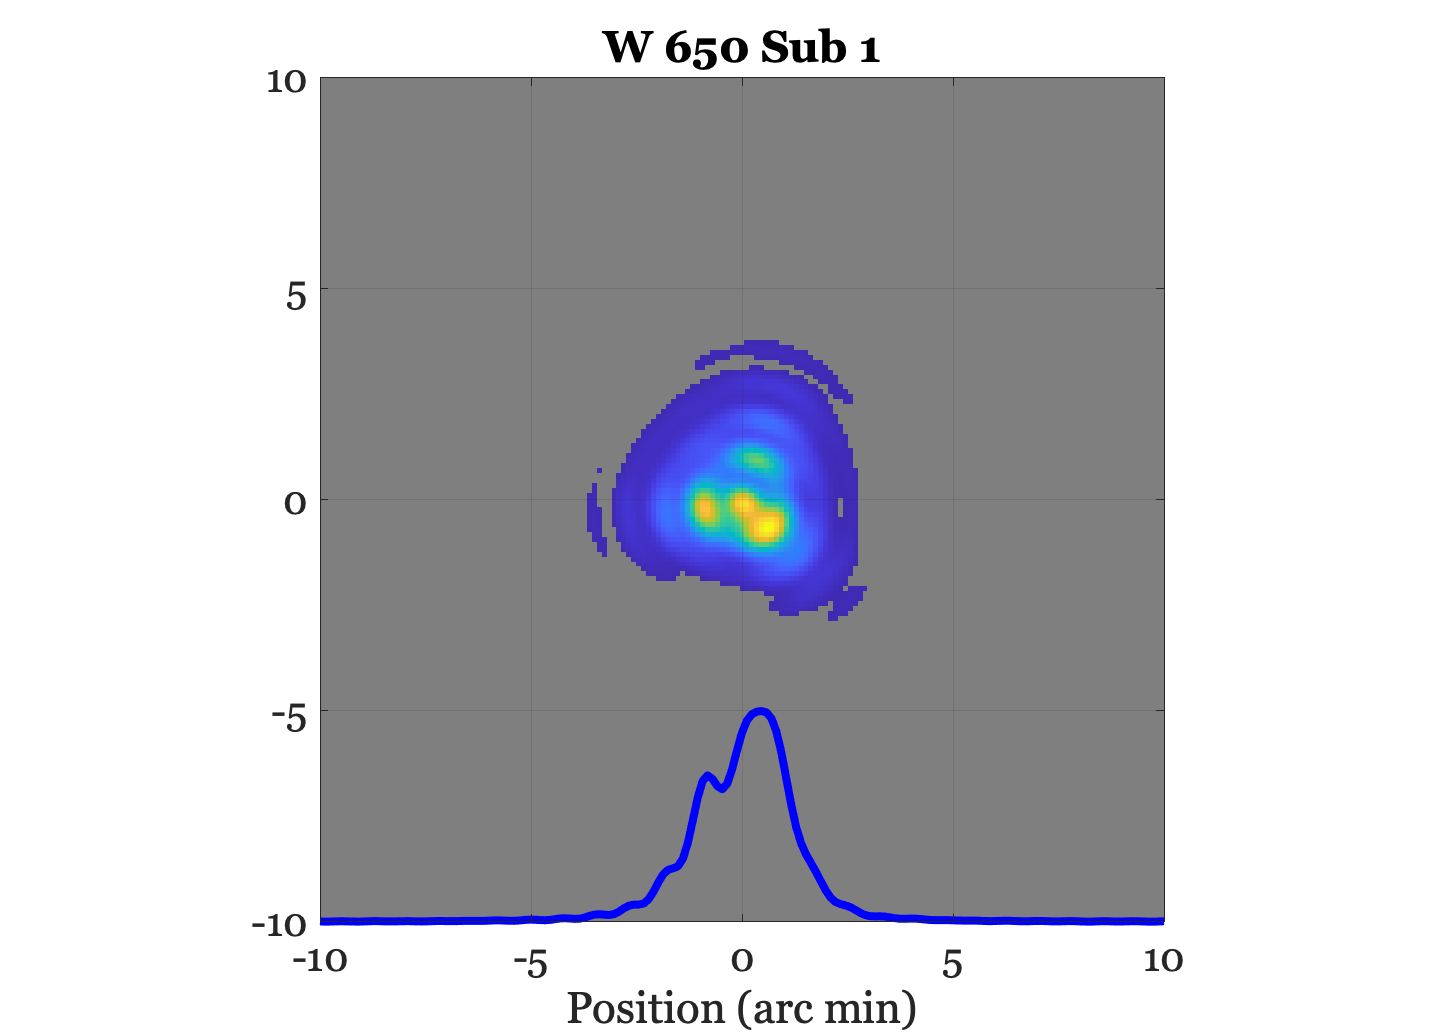

params.wave = [450 550 650];
params.thisSubject = 1;
params.positionDegs =[0 0];

for thisW = params.wave
    
    thisSubject = params.thisSubject;
    positionDegs = params.positionDegs;
    
    [oi, psf, support, zCoeffs, subjID]  = ...
        oiPosition(zCoeffDatabase, 'position',positionDegs, ...
        'pupil diameter', pupilDiamMM, 'subject rank', thisSubject, ...
        'wave',wave, ...
        'eye side', eyeside,'center psf',centerpsf);
    
    idx = find(wave == thisW);
    
    ieNewGraphWin;
    mp = parula(256);
    mp(1:4,:) = repmat([0.5 0.5 0.5],[4,1]);
    imagesc(support.x,support.y,psf(:,:,idx)/max2(psf(:,:,idx)));
    axis image; colormap(mp);
    tMarks  = (-15:5:15); mn = -10; mx = 10;
    set(gca,'xtick',tMarks,'xlim',[mn mx],'ylim',[mn mx]);
    set(gca,'ytick',tMarks);
    grid on;
    hold on; axis xy
    
    % Superimpose the line spread
    lsf = psf2lsf(psf);
    lsf = lsf/sum(lsf(:)); 
    
    % Plot the LSF starting from -10 and scaled to -5.
    thisLSF = lsf(:,idx)/max(lsf(:,idx));
    plot(support.y,5*thisLSF-10,'b-','Linewidth',4);

    title(sprintf('W %d Sub %d',thisW,thisSubject));
    set(gca,'FontSize',20);
    
    xlabel('Position (arc min)');
    if ii == 1
        ylabel('Position (arc min)');
    end
    %{
    % Old
    plot(support.y,lsf(:,idx),'Linewidth',2);
    tMarks  = (-15:5:15); mn = -10; mx = 10;
    set(gca,'xtick',tMarks,'xlim',[mn mx],'ylim',[0 5e-3]);
    %}
end

### Second row

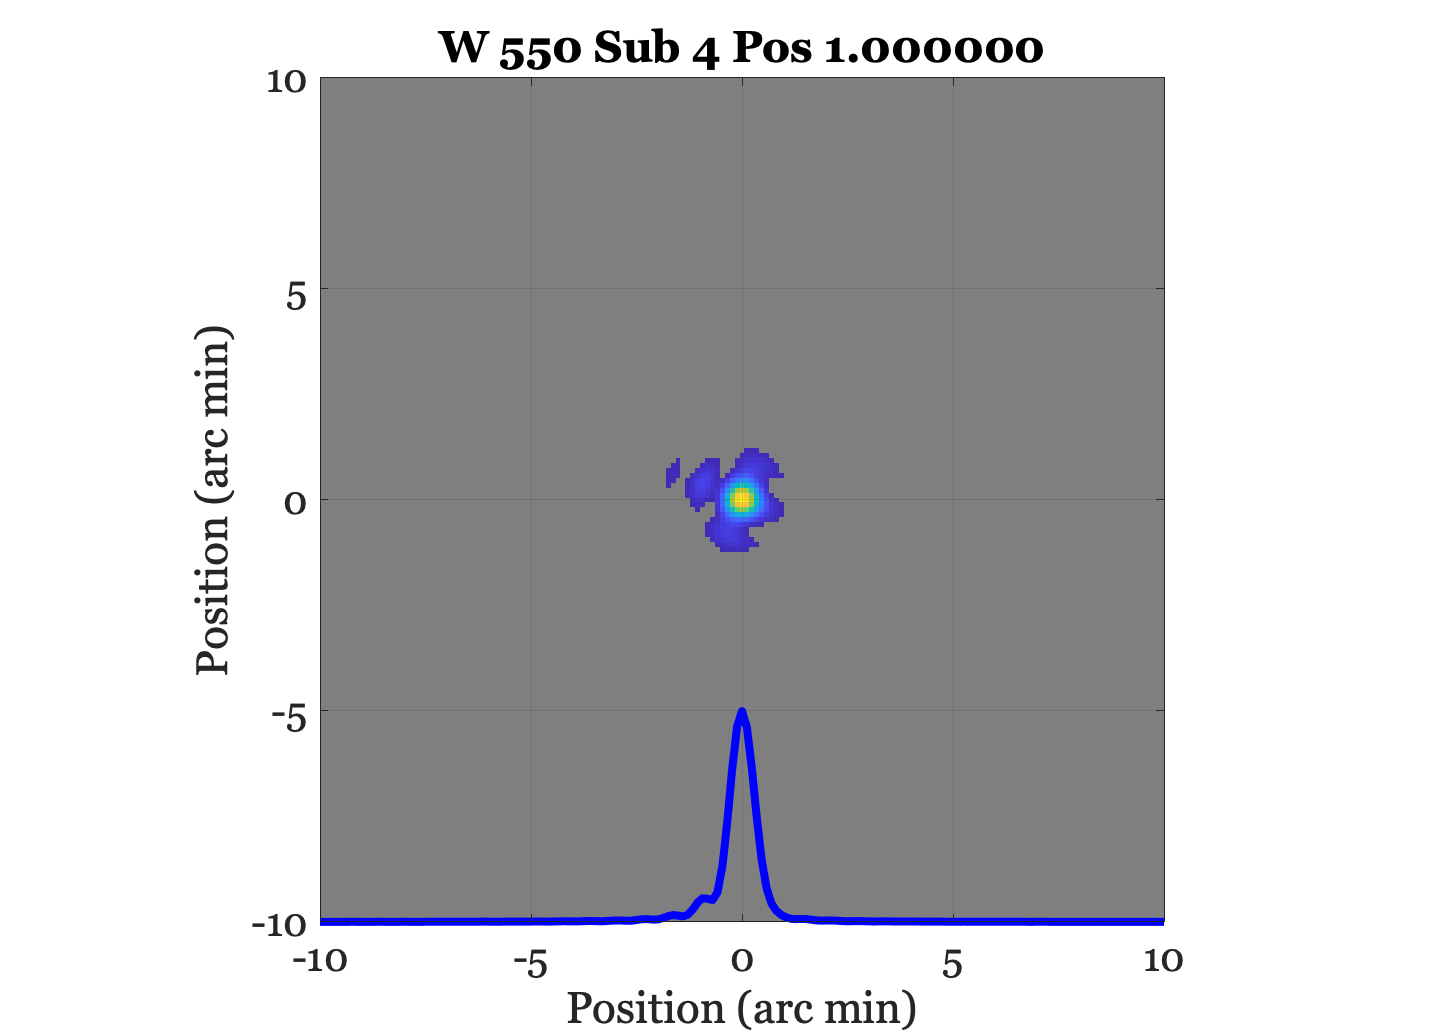

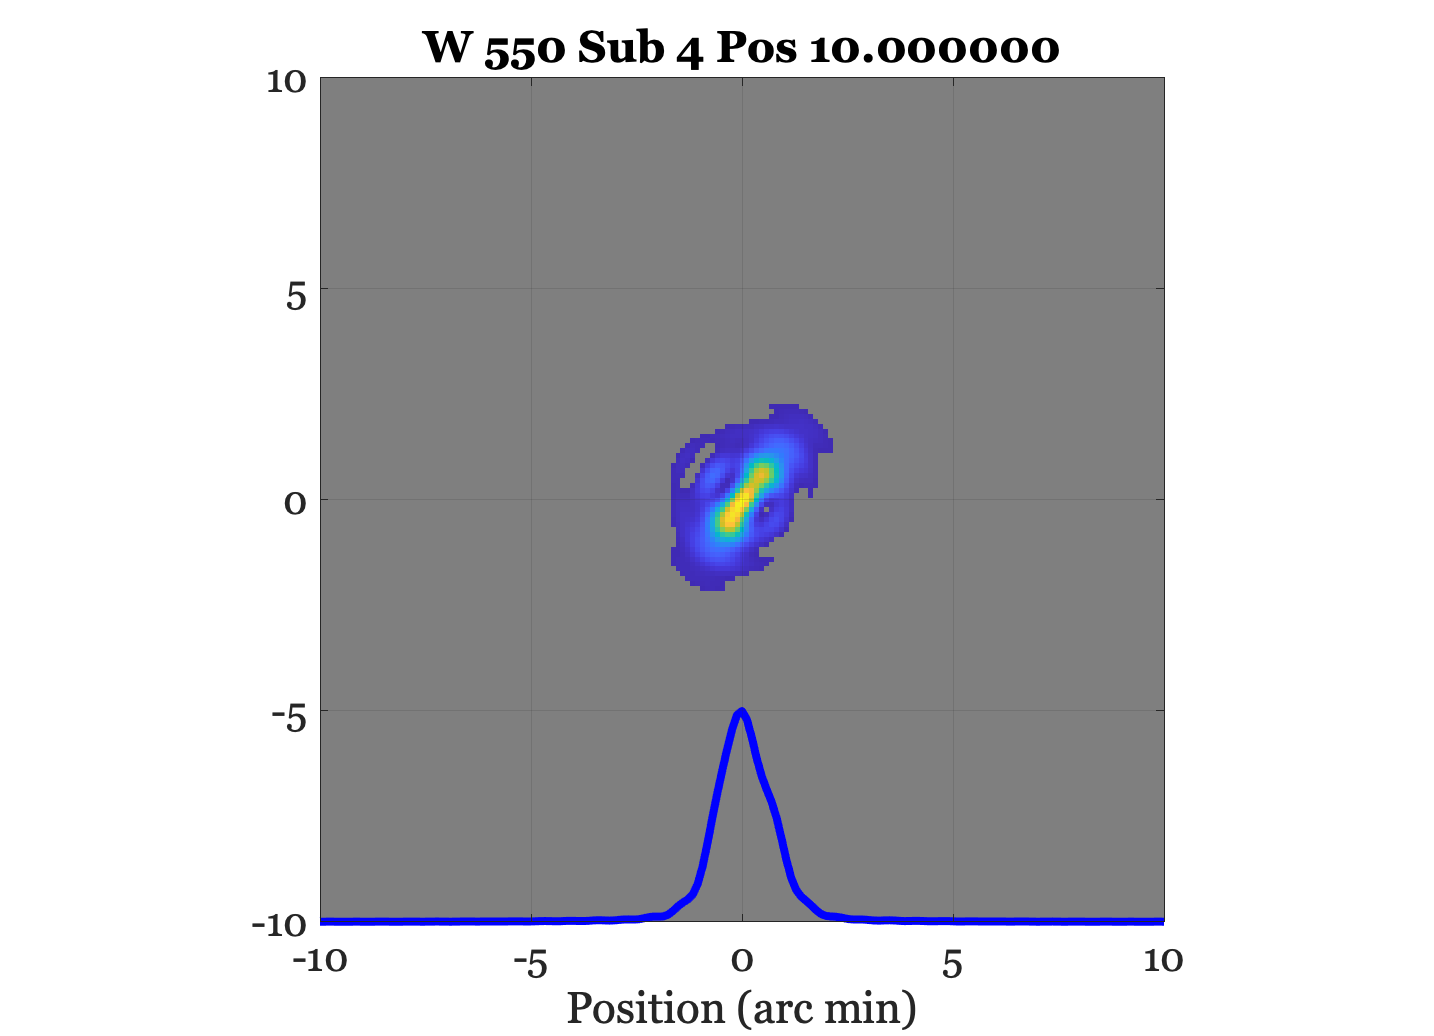

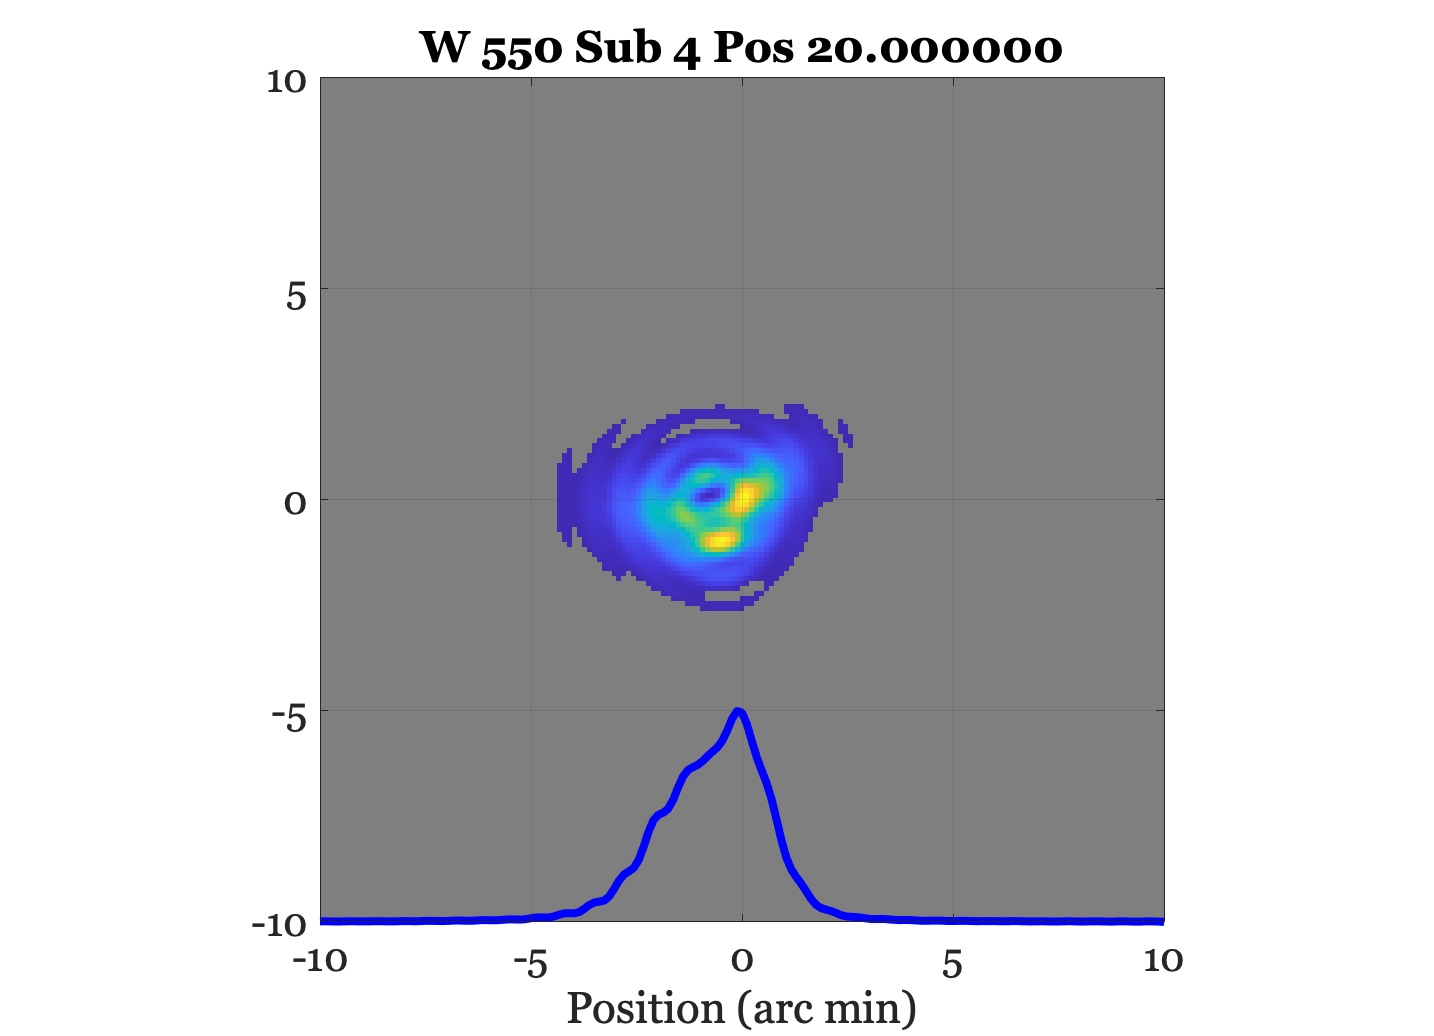

zCoeffDatabase = 'Artal2012';
params.wave = 550;
params.thisSubject = 4;
params.positionDegs =[1 0; 10 0; 20 0];

for ii = 1:3
    positionDegs = params.positionDegs(ii,:);
    thisW = params.wave;
    thisSubject = params.thisSubject;
    
    [oi, psf, support, zCoeffs, subjID]  = ...
        oiPosition(zCoeffDatabase, 'position',positionDegs, ...
        'pupil diameter', pupilDiamMM, 'subject rank', thisSubject, ...
        'wave',wave, ...
        'eye side', eyeside,'center psf',centerpsf);
    
    idx = find(wave == thisW);
    
    ieNewGraphWin;
    mp = parula(256);
    mp(1:4,:) = repmat([0.5 0.5 0.5],[4,1]);
    imagesc(support.x,support.y,psf(:,:,idx)/max2(psf(:,:,idx)));
    axis image; colormap(mp);
    tMarks  = (-15:5:15); mn = -10; mx = 10;
    set(gca,'xtick',tMarks,'xlim',[mn mx],'ylim',[mn mx]);
    set(gca,'ytick',tMarks);
    grid on;
    axis xy
    hold on; 

    lsf = psf2lsf(psf);
    lsf = lsf/sum(lsf(:)); 
    thisLSF = lsf(:,idx)/max(lsf(:,idx));
    plot(support.y,5*thisLSF-10,'b-','Linewidth',4);
        
    title(sprintf('W %d Sub %d Pos %f',thisW,thisSubject,positionDegs(1)));
    set(gca,'FontSize',20);
    
    xlabel('Position (arc min)');
    if ii == 1
        ylabel('Position (arc min)');
    end
    
    
    % Superimp[ose the line spread
    % ieNewGraphWin;
    % lsf = psf2lsf(psf);
    % lsf = lsf/sum(lsf(:));
    % plot(support.y,lsf(:,idx),'Linewidth',2);
    % tMarks  = (-15:5:15); mn = -10; mx = 10;
    % set(gca,'xtick',tMarks,'xlim',[mn mx],'ylim',[0 5e-3]);
end

### Third row

Subject 51 from right eye requires central refraction correction


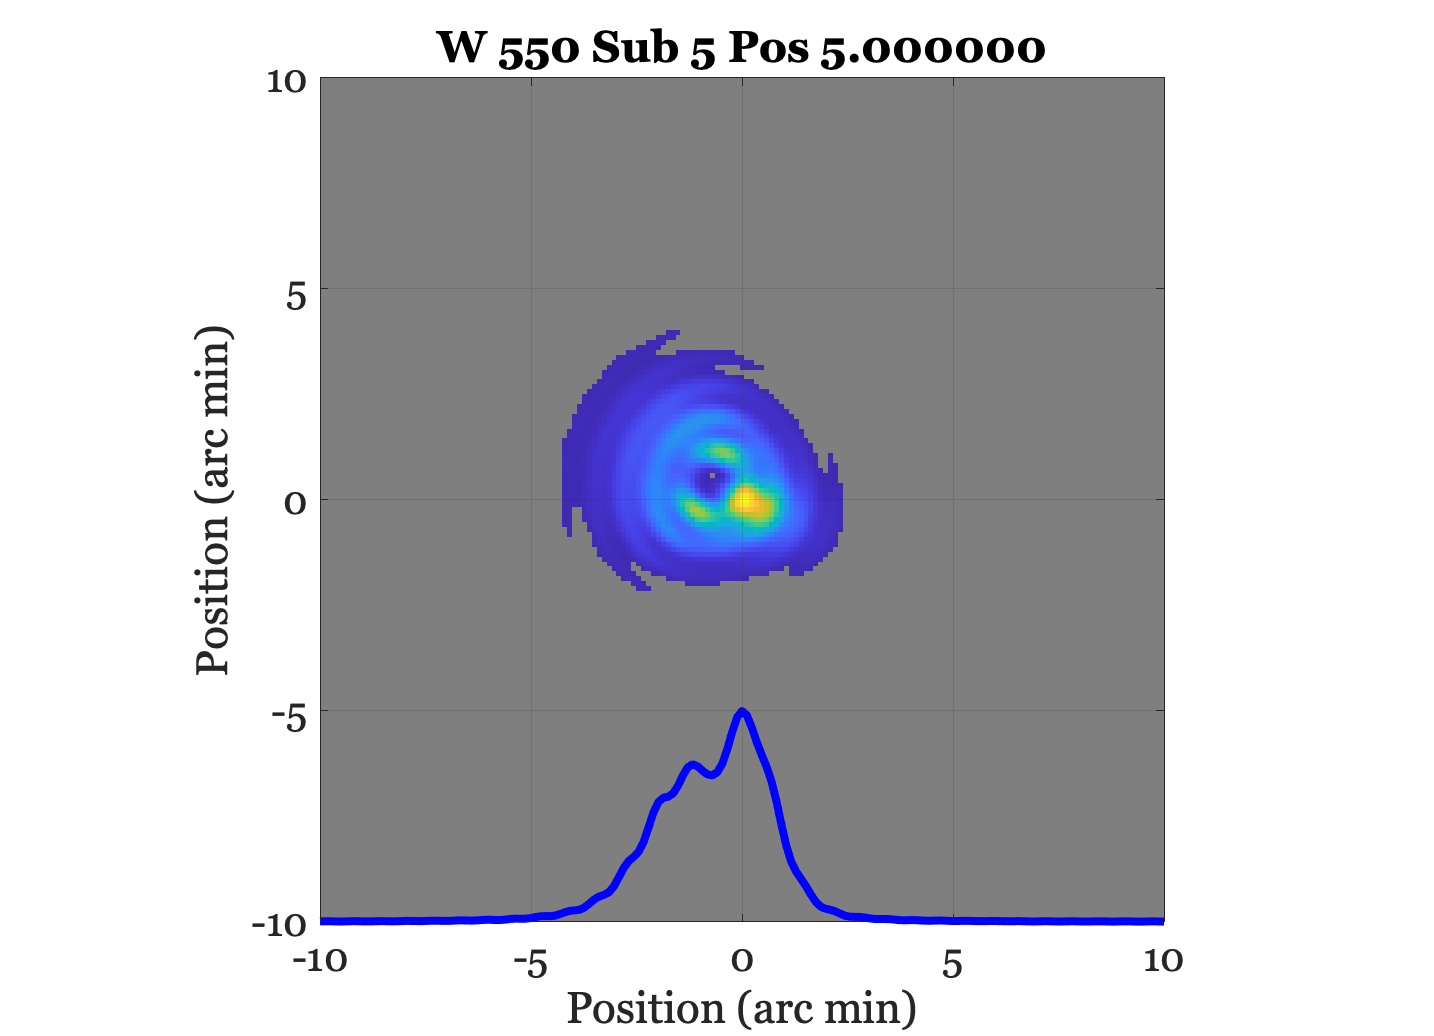

Subject 11 from right eye requires central refraction correction


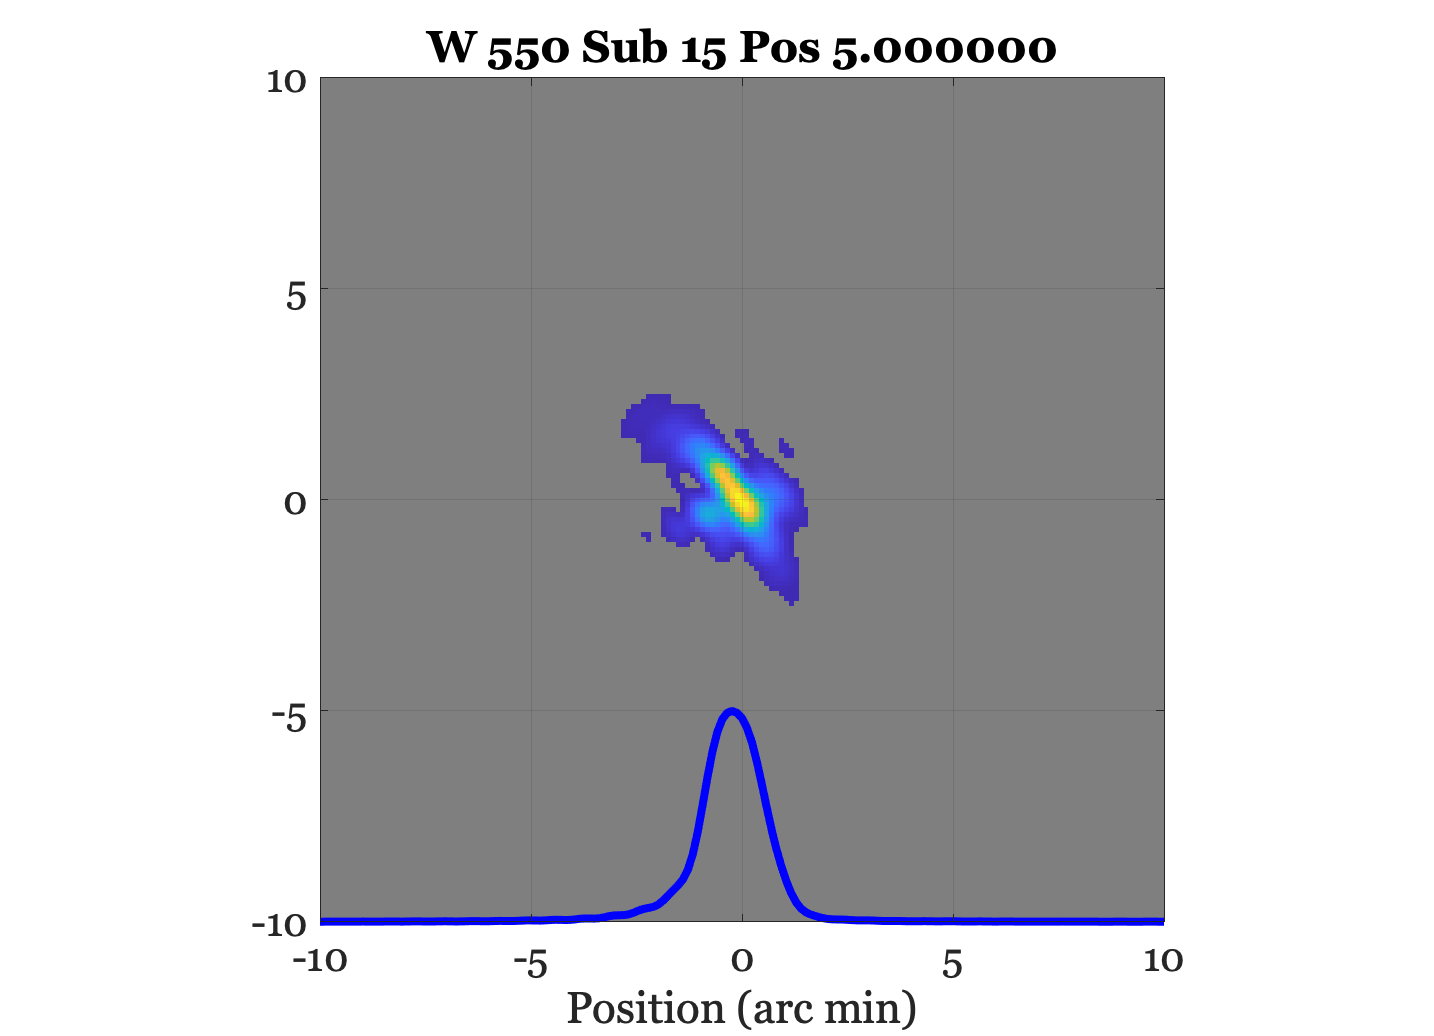

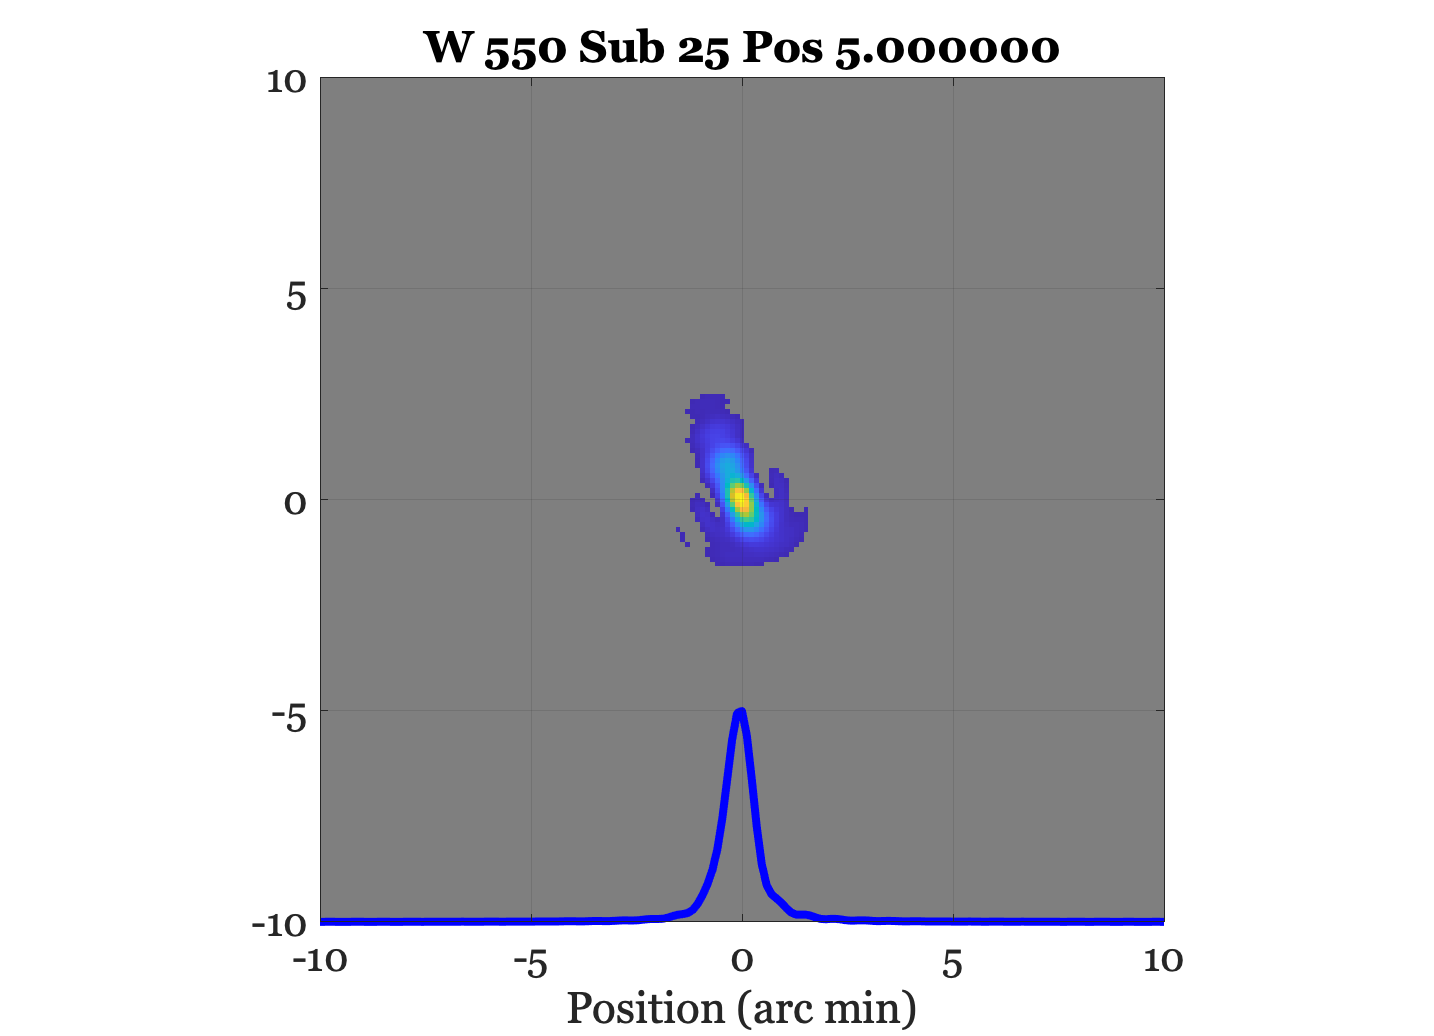

zCoeffDatabase = 'Artal2012';
params.wave = 550;
params.thisSubject = [5 15 25];
params.positionDegs =[5 0];

for ii = 1:3
    positionDegs = params.positionDegs;
    thisW = params.wave;
    thisSubject = params.thisSubject(ii);
    
    [oi, psf, support, zCoeffs, subjID]  = ...
        oiPosition(zCoeffDatabase, 'position',positionDegs, ...
        'pupil diameter', pupilDiamMM, 'subject rank', thisSubject, ...
        'wave',wave, ...
        'eye side', eyeside,'center psf',centerpsf);
    
    idx = find(wave == thisW);
    
    ieNewGraphWin;
    mp = parula(256);
    mp(1:4,:) = repmat([0.5 0.5 0.5],[4,1]);
    imagesc(support.x,support.y,psf(:,:,idx)/max2(psf(:,:,idx)));
    axis image; colormap(mp);
    tMarks  = (-15:5:15); mn = -10; mx = 10;
    set(gca,'xtick',tMarks,'xlim',[mn mx],'ylim',[mn mx]);
    set(gca,'ytick',tMarks);    
    grid on;
    
    axis xy
    hold on; 

    lsf = psf2lsf(psf);
    lsf = lsf/sum(lsf(:)); 
    thisLSF = lsf(:,idx)/max(lsf(:,idx));
    plot(support.y,5*thisLSF-10,'b-','Linewidth',4);
    
    set(gca,'FontSize',20);
        
    xlabel('Position (arc min)');
    if ii == 1
        ylabel('Position (arc min)');
    end
    title(sprintf('W %d Sub %d Pos %f',thisW,thisSubject,positionDegs(1)));

end

% title('')

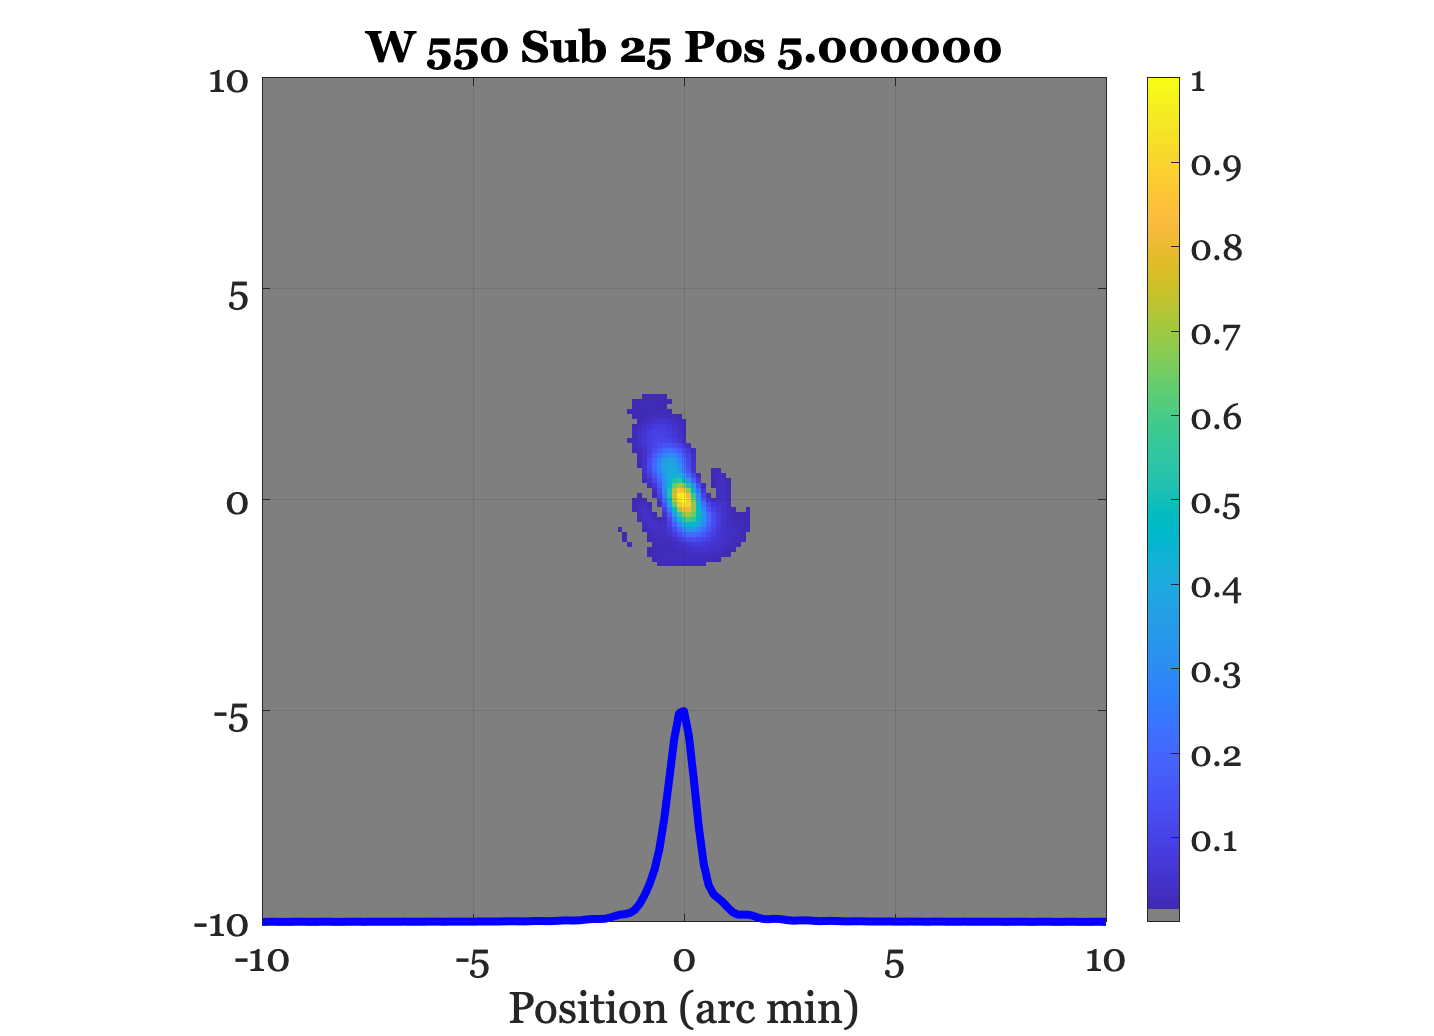

h = colorbar;

## Figure 6 - **Optical shift-invariance. **

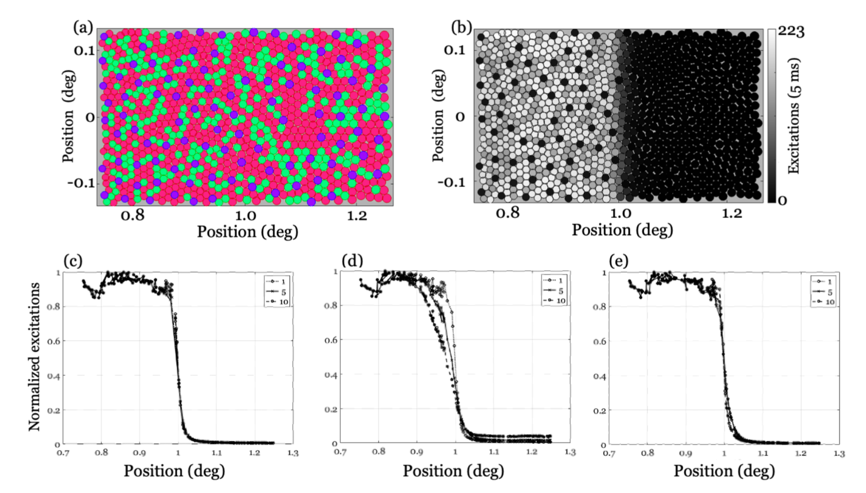

**Optical shift-invariance. **We assess the importance of the optical blur by calculating its impact on the responses in a cone mosaic. In this example, we compare the edge-spread function (ESF) of an edge at three different eccentricities. (a) First we synthesize a typical cone mosaic near 1 deg eccentricity. (b) Then, we compute the number of excitations in each cone in response to a sharp edge (broad spectrum, 5 ms exposure). (c-e) Using wavefront measurements from three different subjects, we compute the L-cone excitations in this mosaic. Each panel is for a different subject. Within each panel we compare the ESF using wavefront data measured at 1◦, 5◦ and 10◦. For two subjects (c,e), the ESF is the same at these eccentricities. For one subject (d) the the edge spread changes with eccentricity. Wavefront data from ISETBio subjects 15, 49 and 51, measured by [Jaeken and Artal, 2012]. The ISETBio script for this figure makes this comparison for many other subjects and stimuli.

Subject 49 from right eye requires central refraction correction
Subject 49 from right eye requires central refraction correction
Subject 49 from right eye requires central refraction correction
Subject 49 from right eye requires central refraction correction
Subject 49 from right eye requires central refraction correction
Subject 49 from right eye requires central refraction correction
Subject 49 from right eye requires central refraction correction


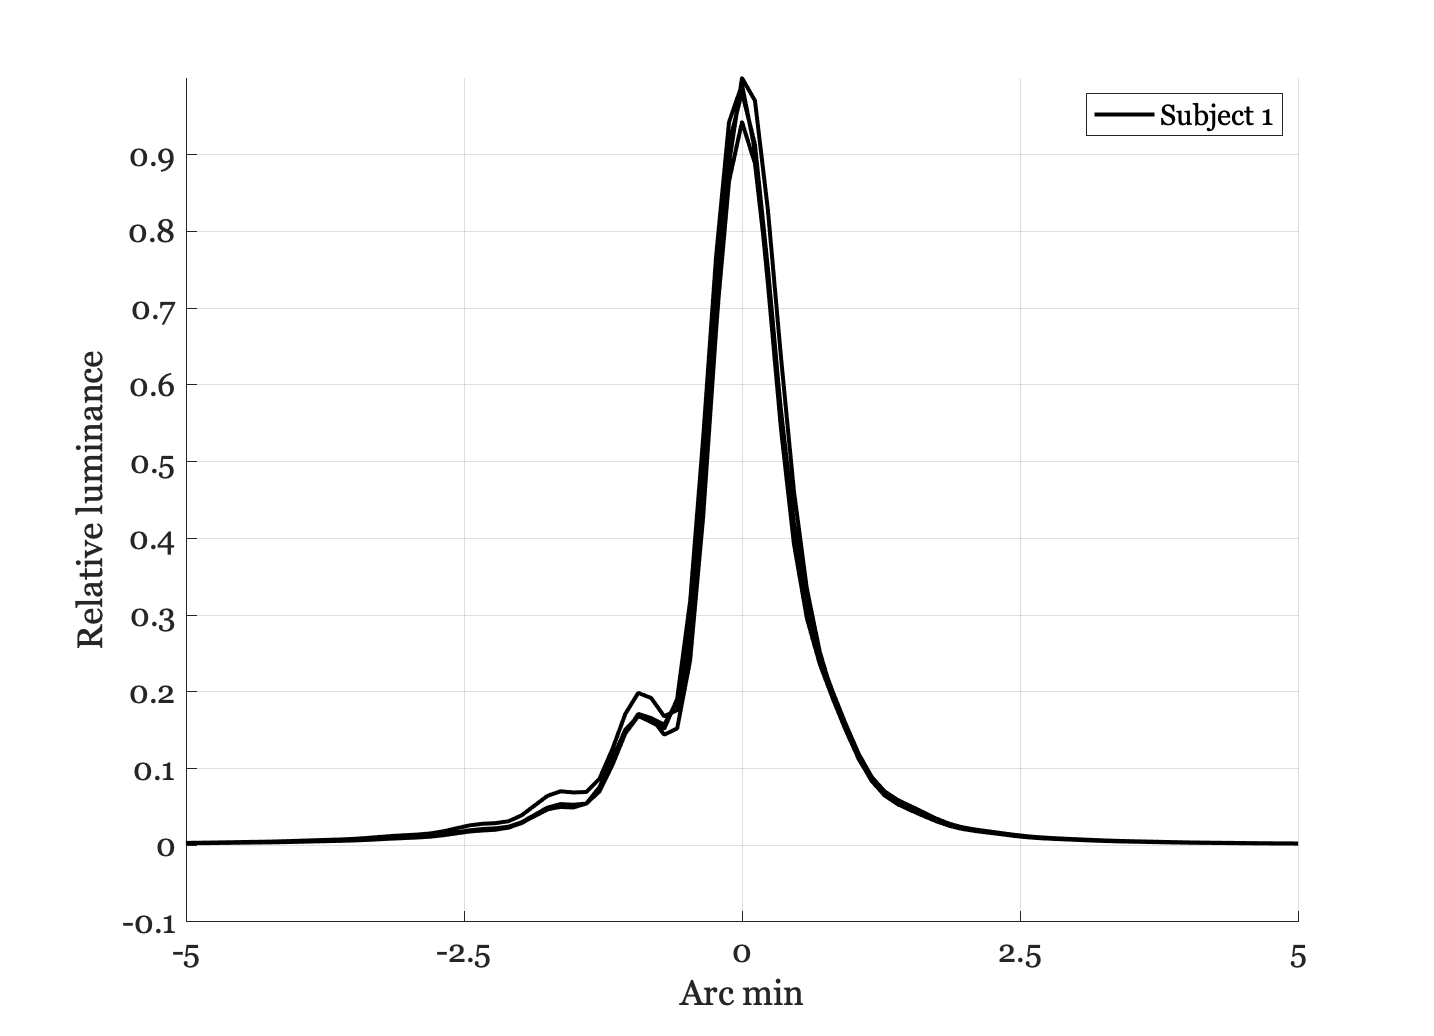

zCoeffDatabase   = 'Artal2012';
subjectRank      = 1; % 1:8; % [2, 5, 10, 20];
eyeside          = 'right';
pupilDiamMM      = 3.0;
centerpsf        = true;
wave             = 400:10:700;

pos = -3:1:3;

for thisSubject = subjectRank
    lsf = zeros(201,numel(wave),numel(pos));
    for ii=1:numel(pos)
        positionDegs     = [pos(ii) 0];   % v

        [oi, psf, support, zCoeffs, subjID]  = ...
            oiPosition(zCoeffDatabase, 'position',positionDegs, ...
            'pupil diameter', pupilDiamMM, 'subject rank', thisSubject, ...
            'wave',wave, ...
            'eye side', eyeside,'center psf',centerpsf);

        % x, w, pos
        lsf(:,:,ii) = psf2lsf(psf);
    end

    % Find the luminance weighted sum (luminance)

    lumLSF = zeros(201,numel(pos));
    vLambda = ieReadSpectra('Vlambda',wave);
    for ii=1:numel(pos)
        lumLSF(:,ii) = lsf(:,:,ii)*vLambda(:);
    end

    lumLSF = lumLSF/max(lumLSF(:));

    % Show as line plots

    ieNewGraphWin;
    hold on;
    for ii=1:2:numel(pos)
        if abs(pos(ii)) <= 4
            plot(support.y,lumLSF(:,ii),'k-','Linewidth',2);
        end
    end
    grid on;
    xlabel('Arc min'); ylabel('Relative luminance')
    set(gca,'ylim',[-0.1 1]); set(gca,'xlim',[-5 5]);
    set(gca,'xtick',(-5:2.5:5));
    legend(sprintf('Subject %d',thisSubject));
    drawnow; pause(0.5);
    print(sprintf('LSF_%s_%d',zCoeffDatabase,thisSubject),'-dpng');
end


%% Show multiple waves

wavesamples = [400, 450, 500, 550, 600, 650];

leg = cell(numel(wavesamples),1);
for ii=1:numel(wavesamples)
    leg{ii} = [num2str(wavesamples(ii)),' nm'];
end

%%
ieNewGraphWin;
hold on;
for ii=1:numel(wavesamples)
    idx = find(wave == wavesamples(ii));
    plot(support.y,lsf(:,idx),'Linewidth',2);
end
set(gca,'xlim',[-8 8],'ylim',[0 1]);
legend(leg);
xlabel('Arc min'); ylabel('Relative intensity');
grid on;

%%

lsfs = zeros(201,numel(pos));
for ii=1:numel(pos)
    tmp = squeeze(lsf(:,idx,ii));
    thisLSF = lsf(:,idx,ii)/sum(lsf(:,idx,ii));
    lsfs(:,ii) = thisLSF;
end

%% Show as a surface
surf(pos,support.y,lumLSF);
xlabel('Eccentricity (deg)'); ylabel('Arc min');
set(gca,'ylim',[-5 5]);
title(sprintf('Artal data, Subj rank: %d',subjectRank));


%%  Compare at a single wavelength

thisWave = 450;
idx = find(wave == thisWave);

lsfs = zeros(201,numel(pos));
for ii=1:numel(pos)
    tmp = squeeze(lsf(:,idx,ii));
    thisLSF = lsf(:,idx,ii)/sum(lsf(:,idx,ii));
    lsfs(:,ii) = thisLSF;
end

%{
ieNewGraphWin;
hold on;
for ii=1:numel(pos)
   plot(support.x,lsfs(:,ii));
end
%}

%% Highest resolution

ieNewGraphWin;
surf(pos,support.y,lsfs);
xlabel('Eccentricity (deg)'); ylabel('Arc min');
colormap(cool);
title(sprintf('Wave %d',thisWave));

%%  Sampled at 0.5 min which is the cone density in the fovea

possamples = (0:1:10);
% arcmin = support.y(:);
% possamples = pos;
arcmin = (-10:0.5:10)';
lsfsInterp = interp2(pos(:),support.y(:),lsfs,possamples,arcmin);

ieNewGraphWin;
surf(possamples,arcmin,lsfsInterp);
xlabel('Eccentricity (deg)'); ylabel('Arc min');
title(sprintf('Wave %d',thisWave));

%%
%{
surf(possamples',arcmin(:),sInterp);
xlabel('Eccentricity (deg)'); ylabel('Arc min');
colormap(cool);
%}
%%
%{
xlabel('arc min'); ylabel('relative intensity');
imagesc(support.x, support.y, squeeze(psf(:,:,idx)));
axis 'square'; colormap(gray); xlabel('arc min'); ylabel('arc min');
%}
%% Try putting the zCoeffs for a subject into an oi

scene = sceneCreate('slanted edge', 512, Inf);
scene = sceneSet(scene,'fov',2);
% scene = sceneCrop(scene,[128 160 512 64]);

cmP = cMosaicParams;
cmP.positionDegs = [1,0];
cmP.sizeDegs = [0.5 0.3];
cm = cMosaic(cmP);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 2).
min cone aperture diameter = 2.566750 microns


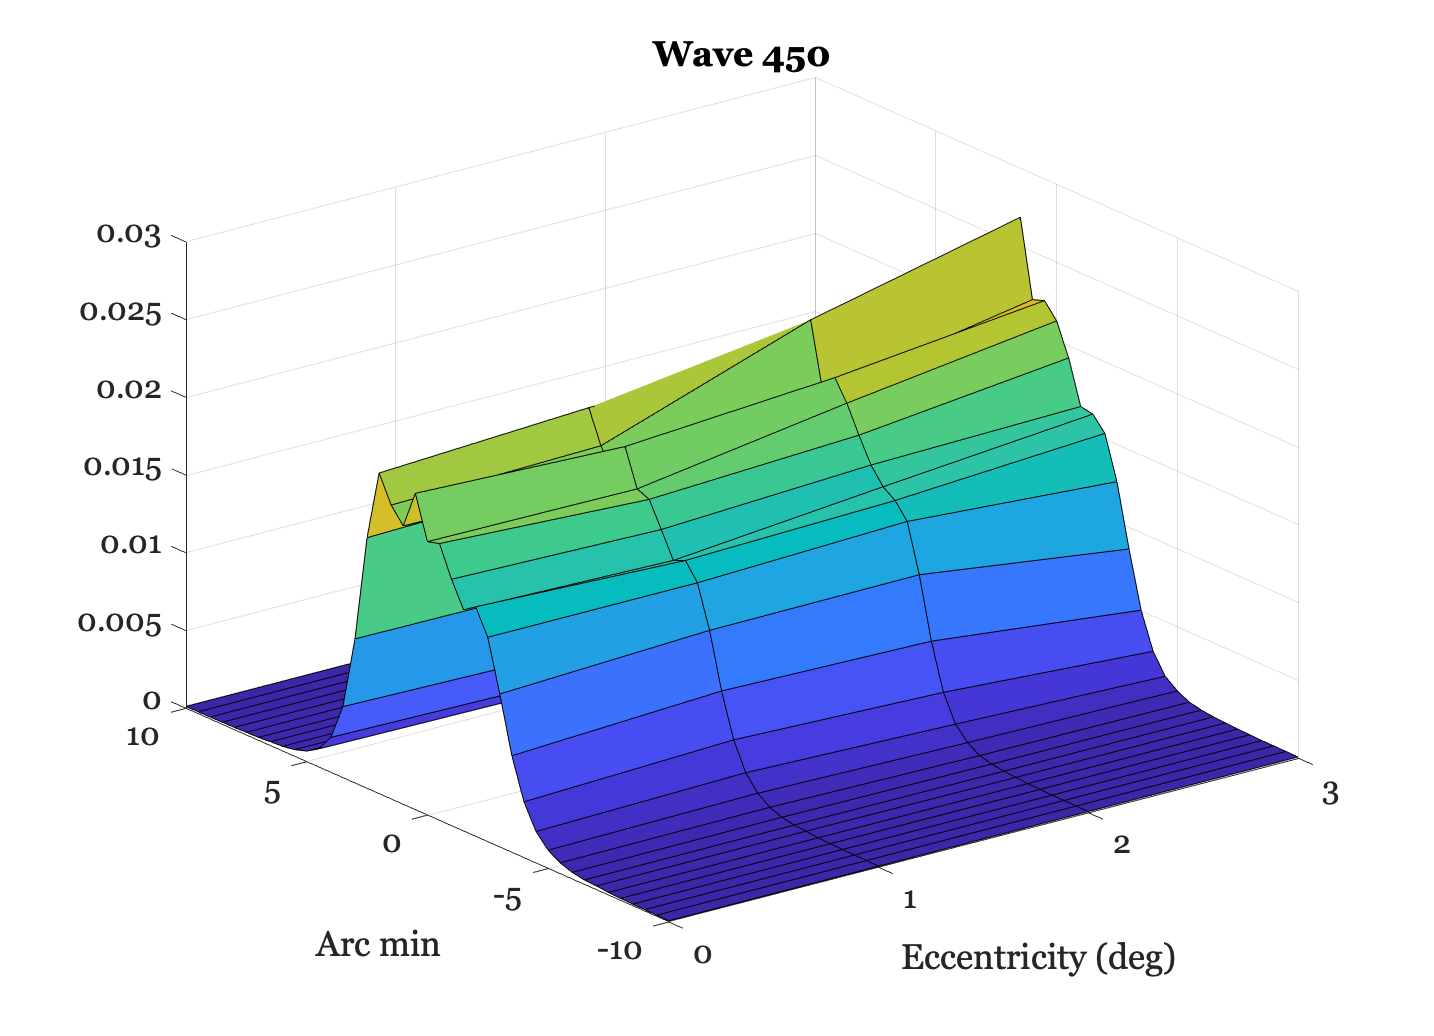

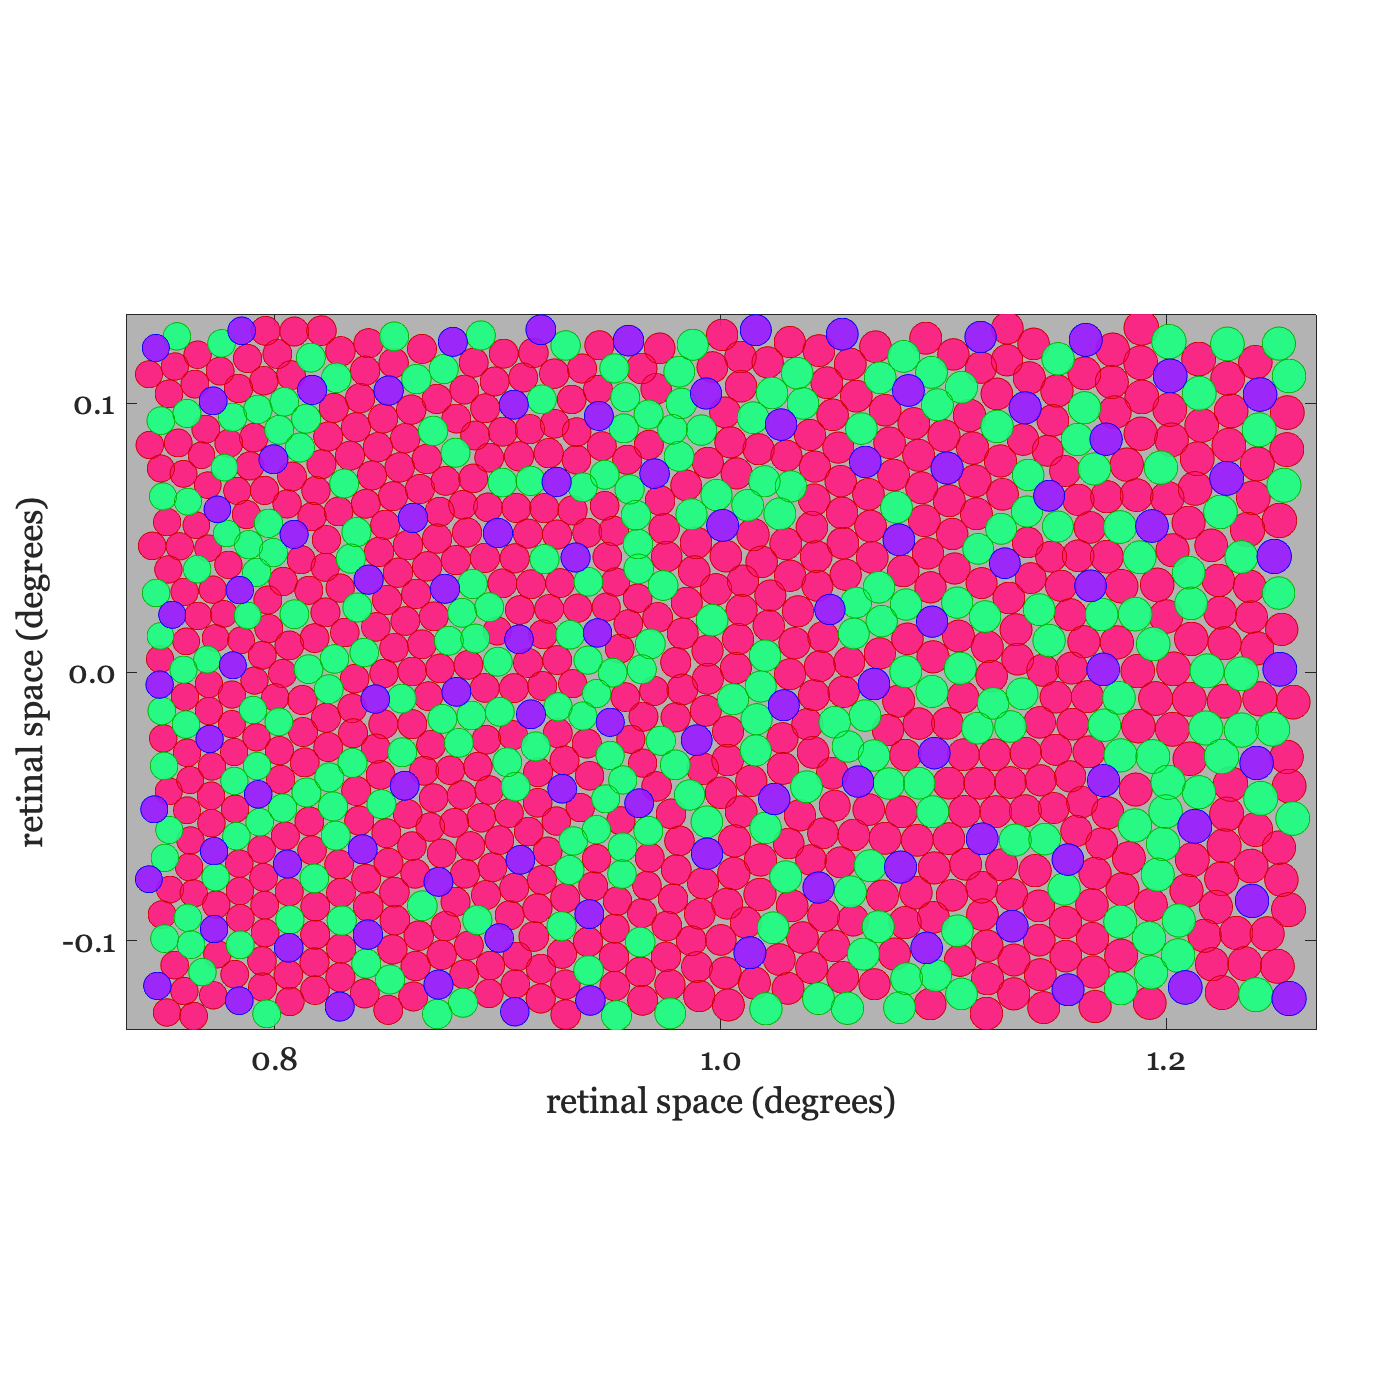


cm.integrationTime = 0.05;
cm.visualize;

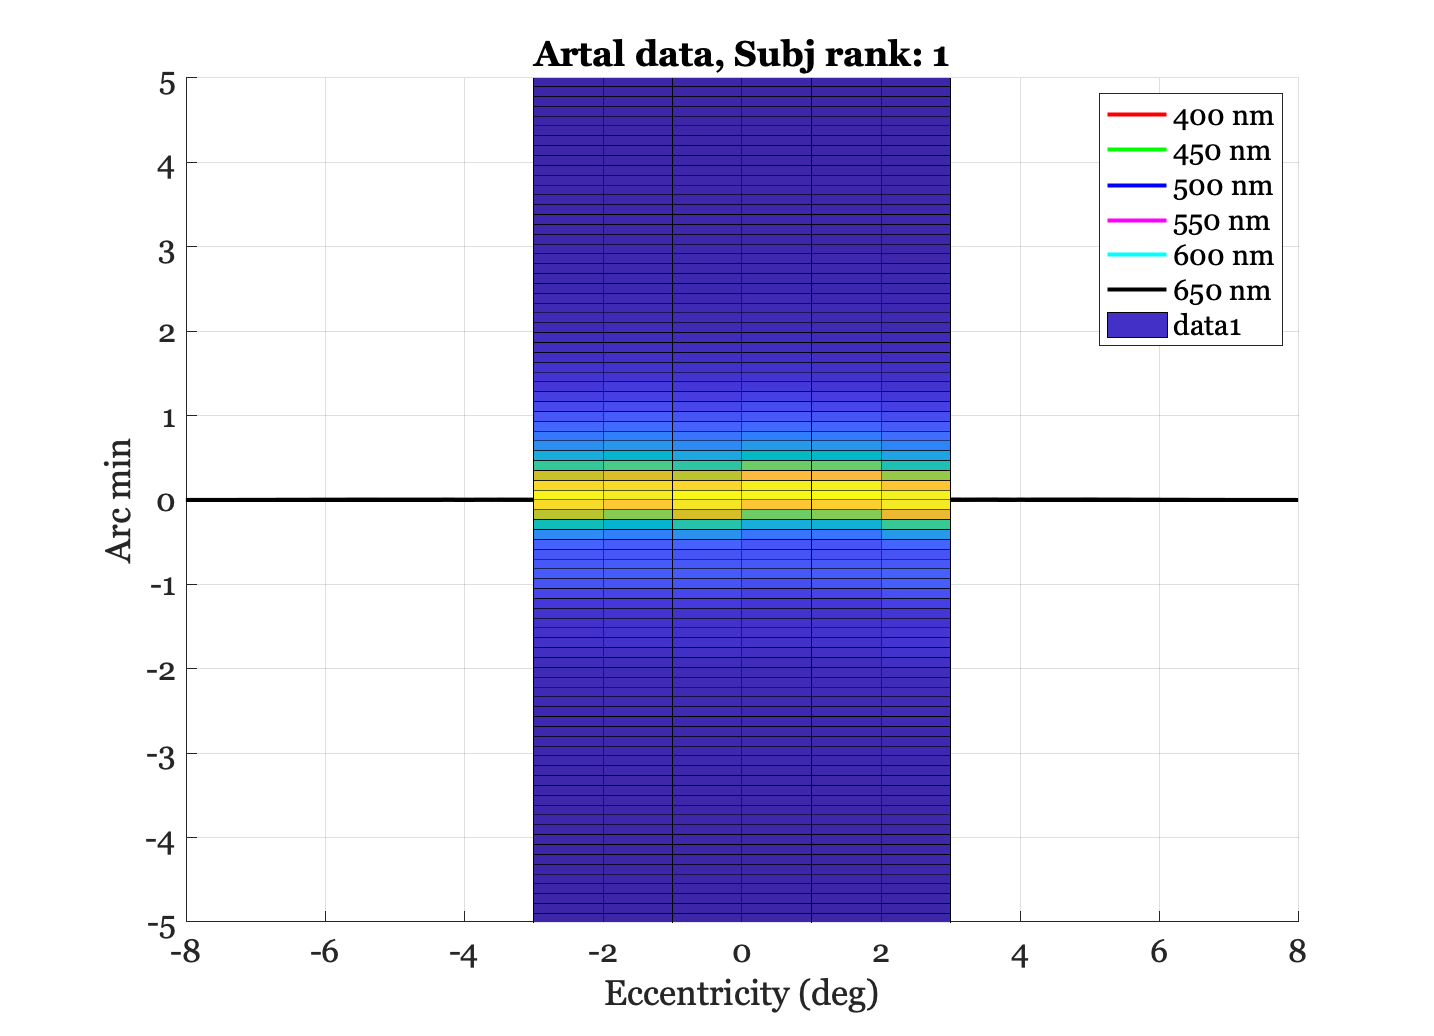

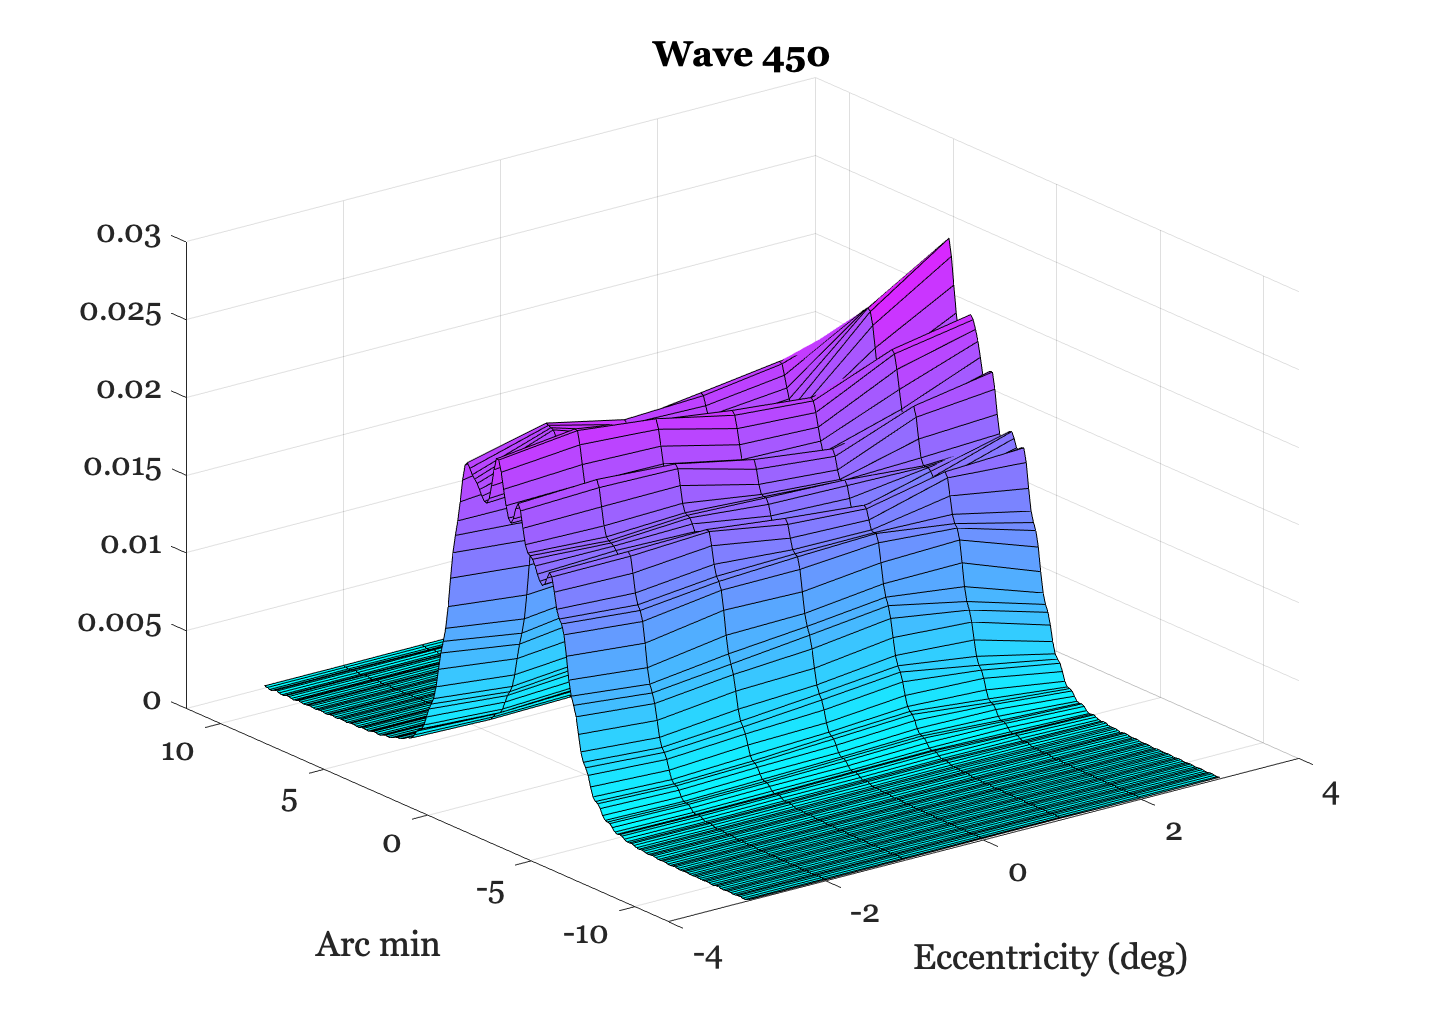


%%  Make a test scene
params = harmonicP;
params.freq = 80;
params.row = 1024; params.col = 1024;
scene = sceneCreate('harmonic',params);
scene = sceneSet(scene,'fov',10);
sceneWindow(scene);

Subject 15 from right eye requires central refraction correction


min cone aperture diameter = 1.716243 microns


Subject 15 from right eye requires central refraction correction


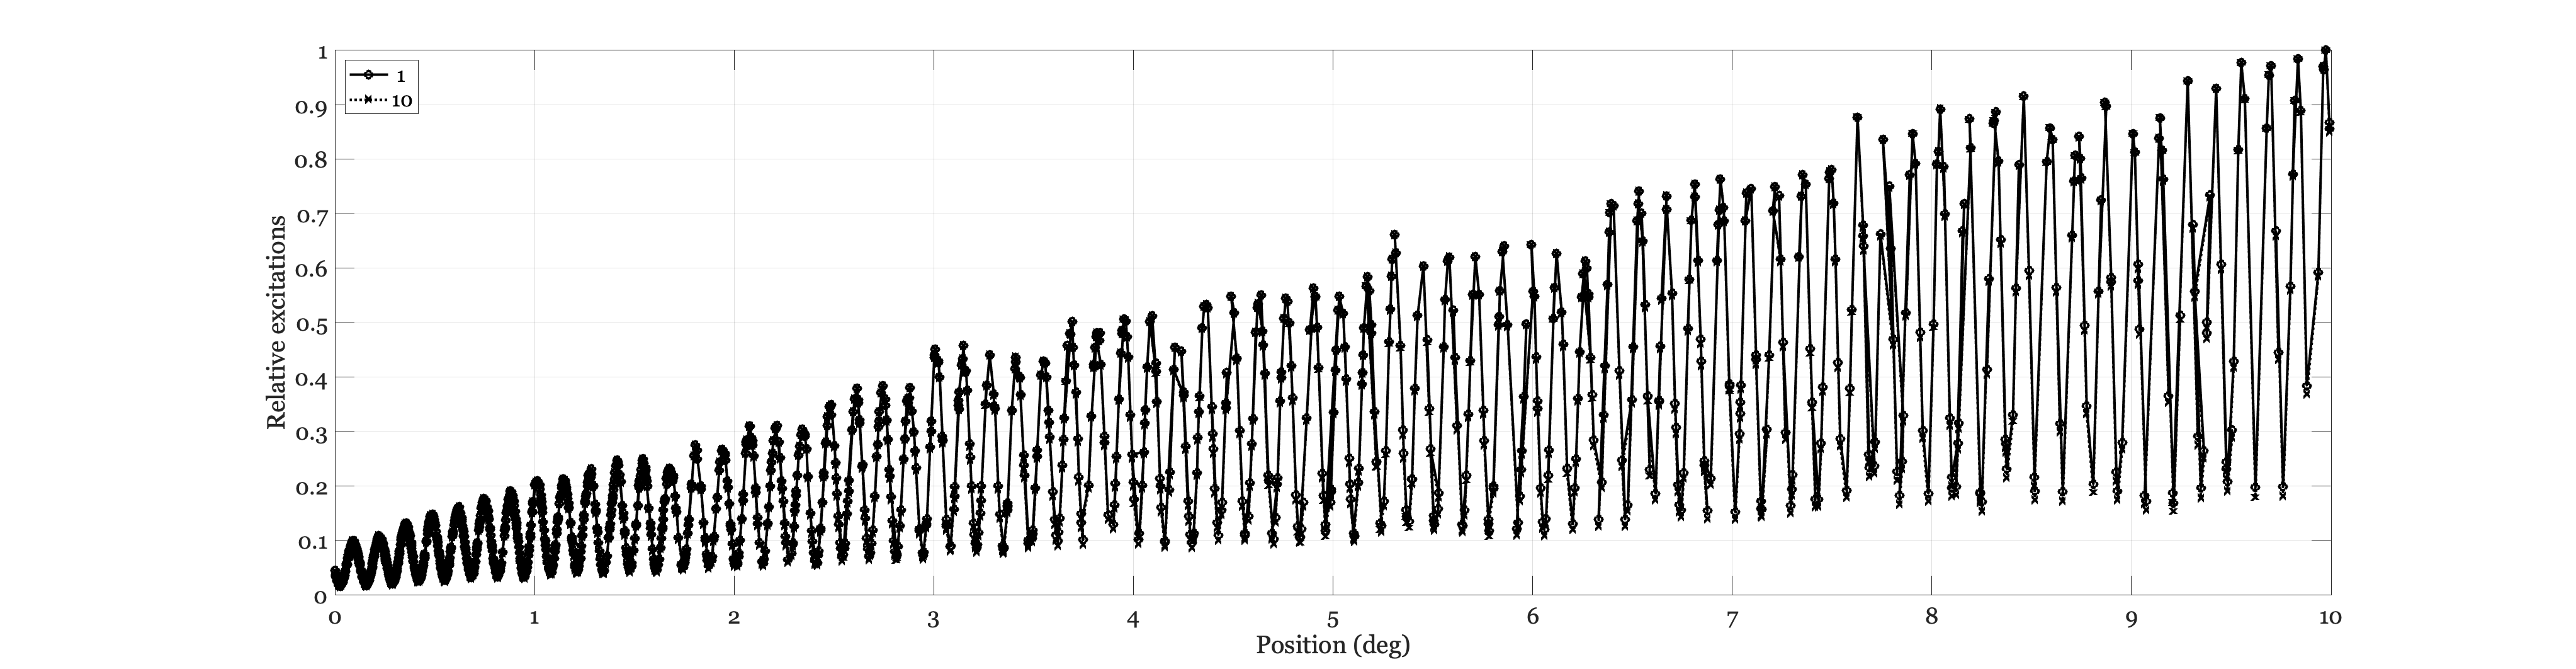

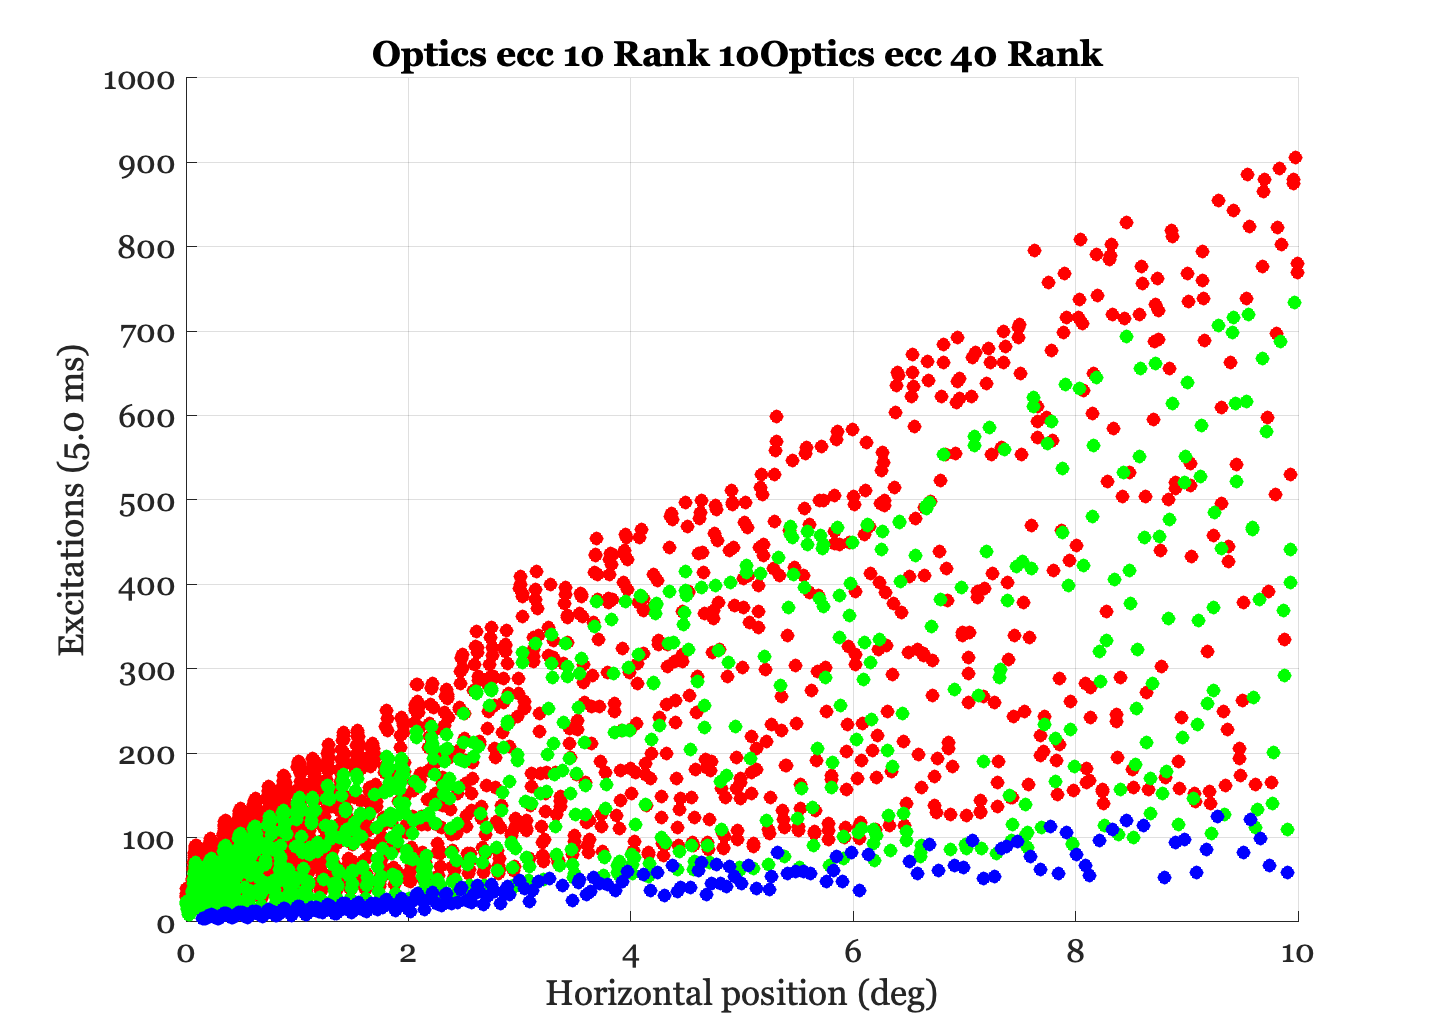

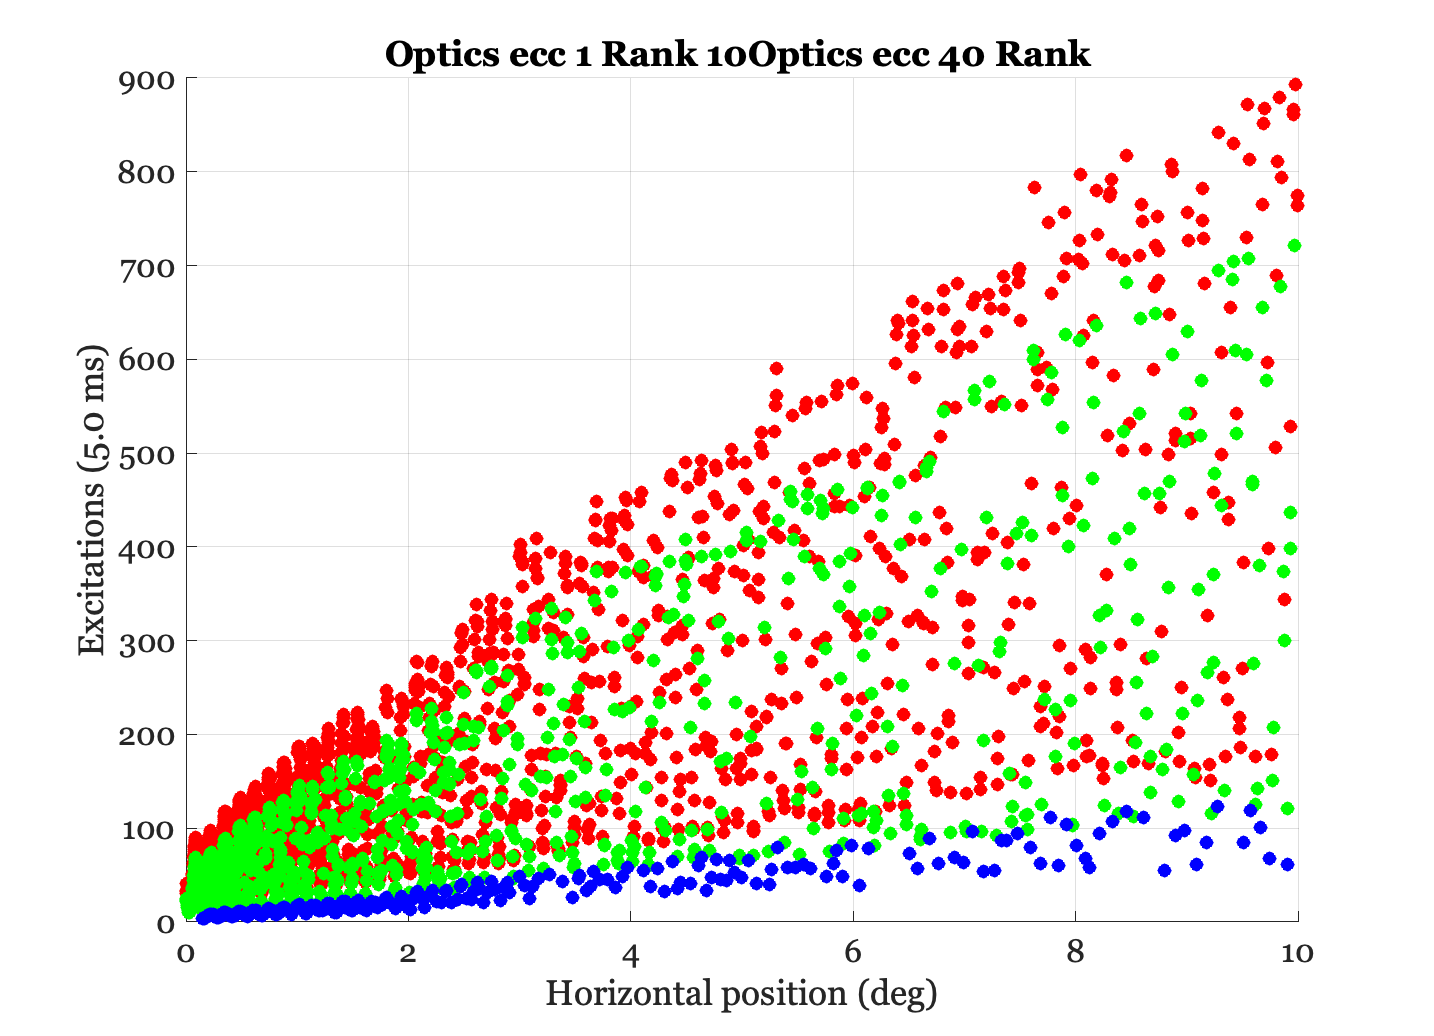

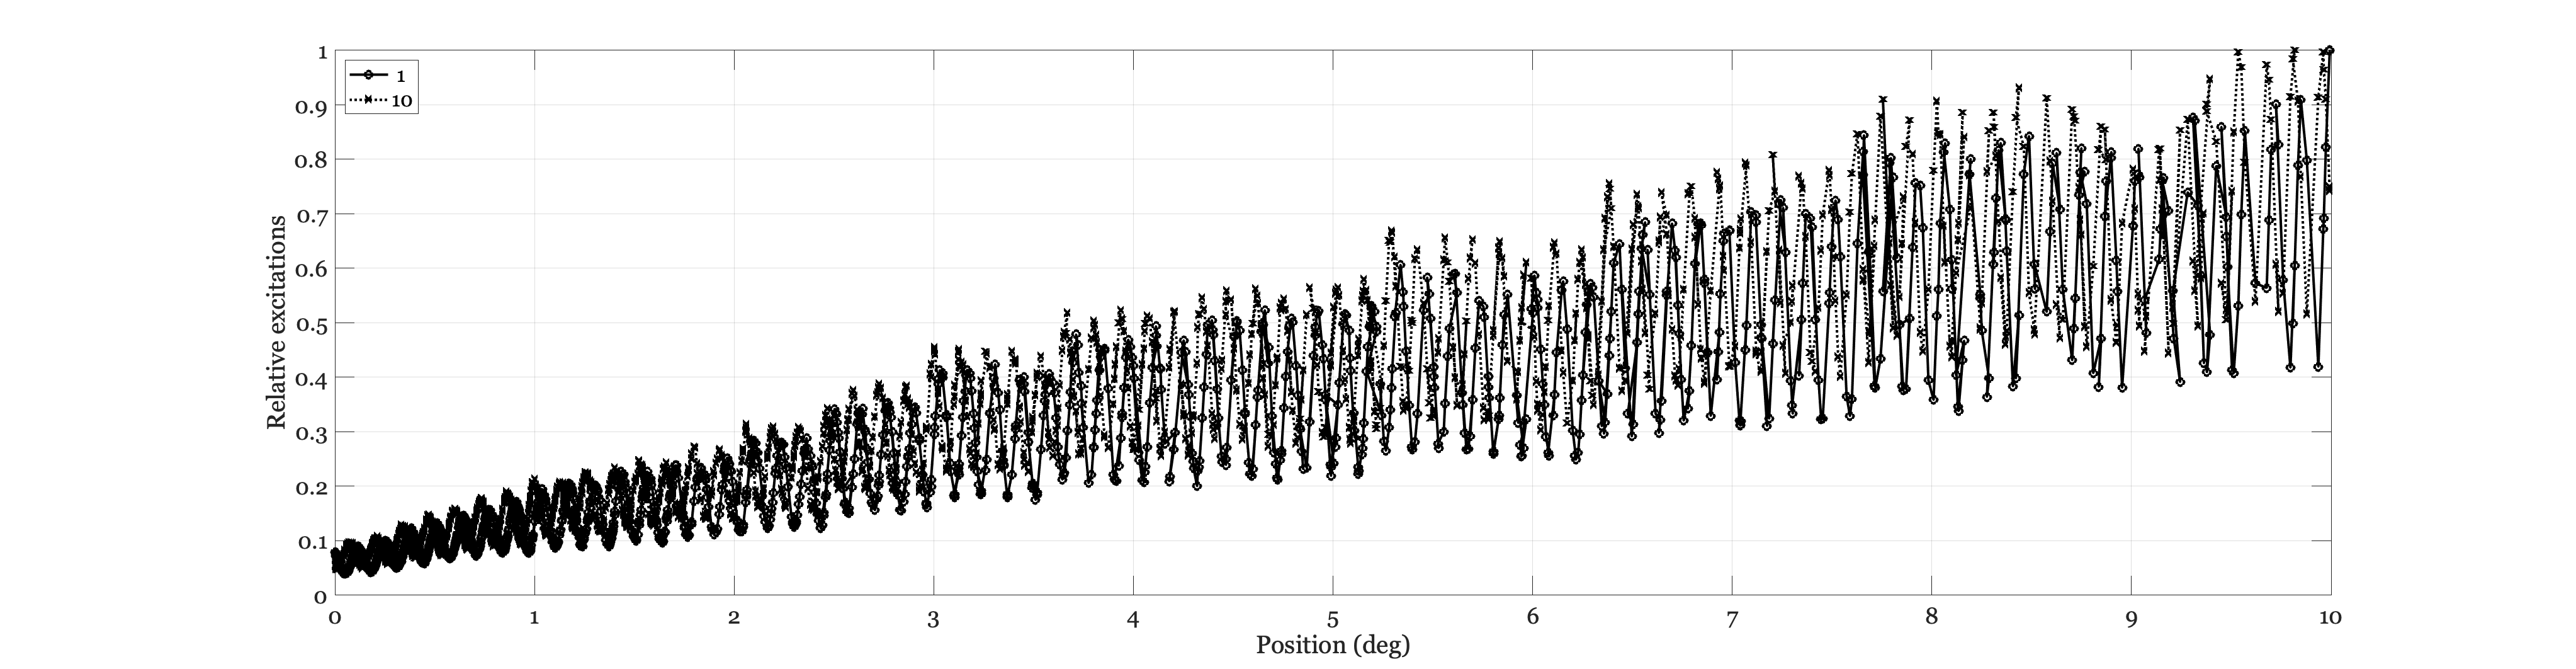

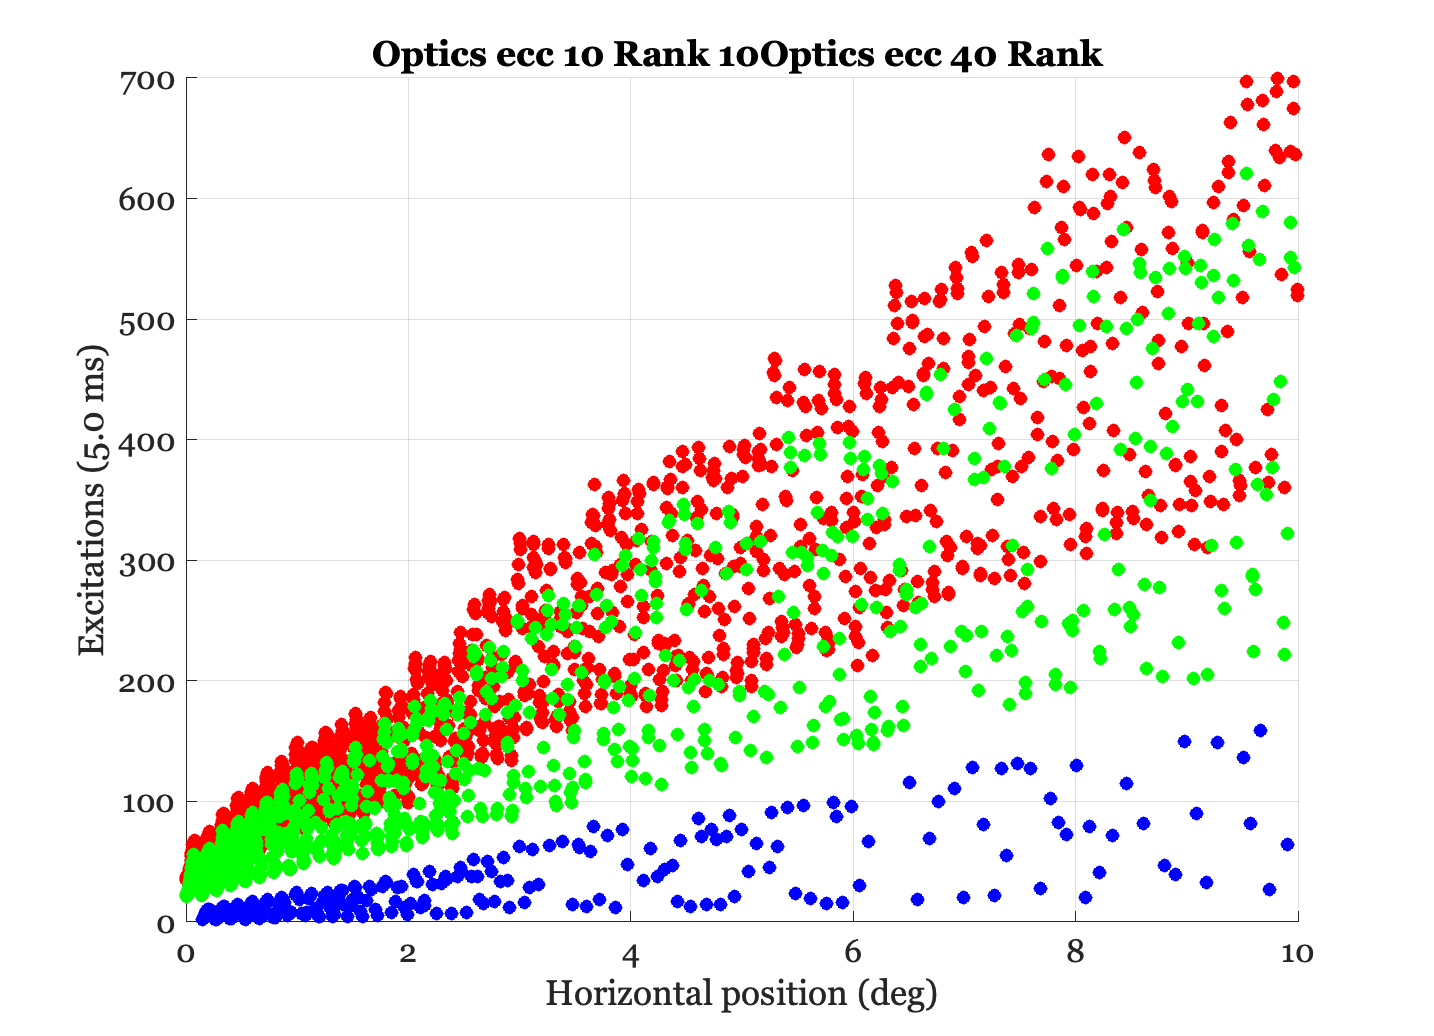

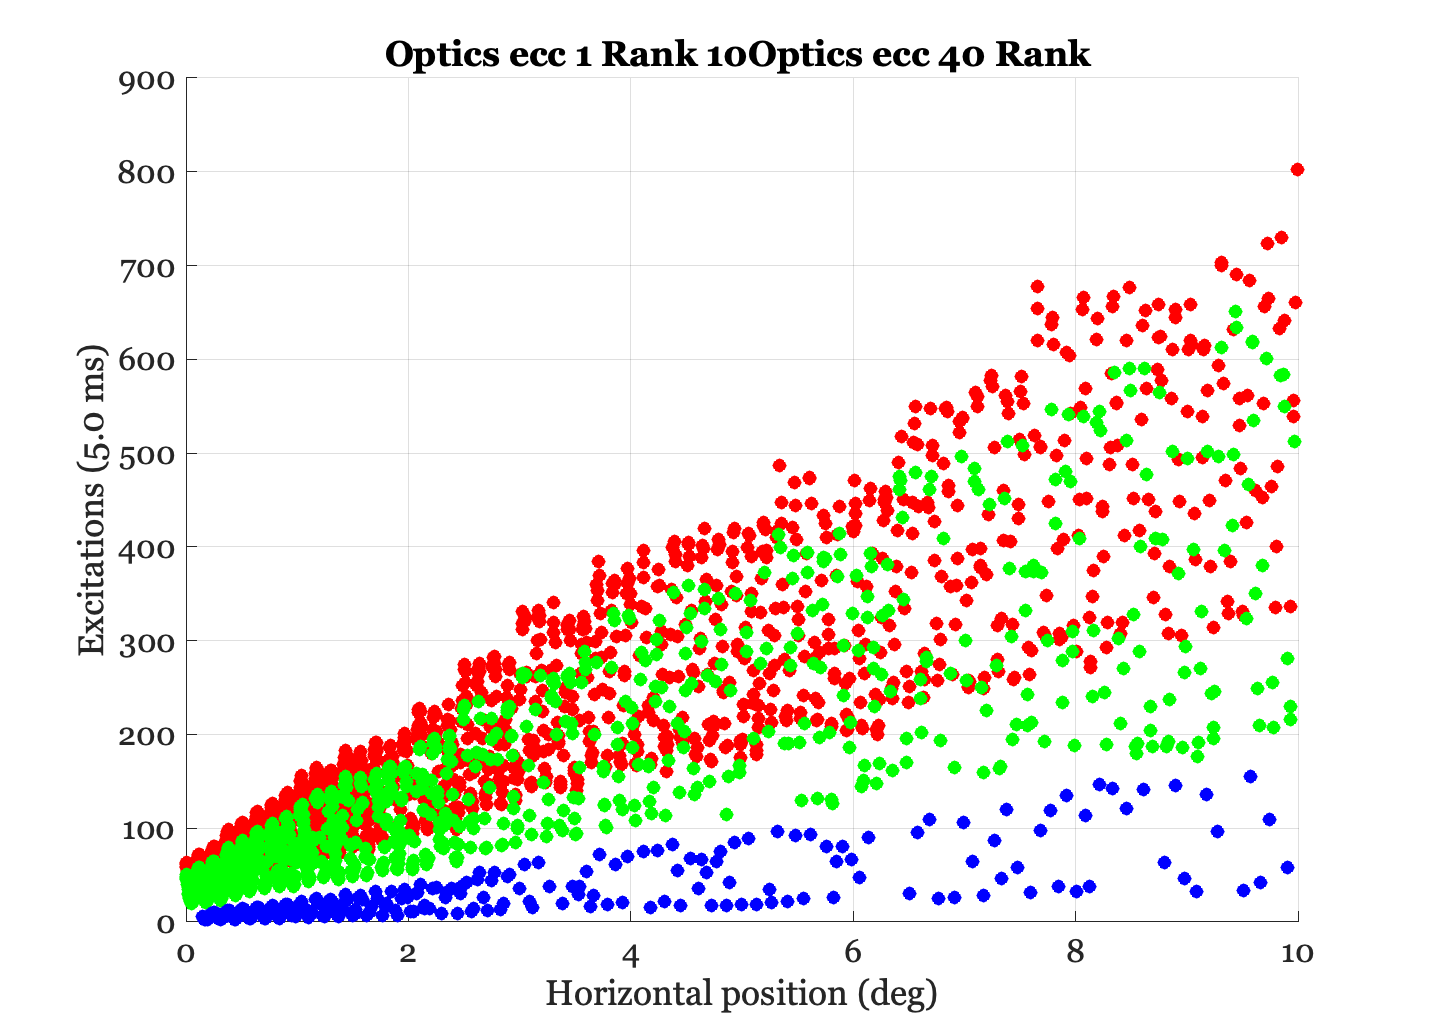


%% Set up parameters and make the cMosaic

zCoeffDatabase   = 'Artal2012';
eyeside          = 'right';
pupilDiamMM      = 3.0;
centerpsf        = true;
wave             = 400:10:700;

ecc = [1,10]; % [1 3 5]
cmP.positionDegs = [5,0];
cmP.sizeDegs = [10 0.5]; % [0.5 0.3];

fname = fullfile(thisDir,"cm10deg.mat");
%{
cm = cMosaic(cmP);
% cm.visualize;

save(fname,'cm');
%}
load(fname,'cm');

%% Loop through some subjects.

subjectRank      = [10, 40];
hdl = ieNewGraphWin;
for ss = 1:numel(subjectRank)
n = 0;
uData = cell(numel(ecc),1);
for ii = ecc
    n = n + 1;
    positionDegs = [ii 0];

    [oi, psf, support, zCoeffs, subjID]  = ...
        oiPosition(zCoeffDatabase, 'position',positionDegs, ...
        'pupil diameter', pupilDiamMM, 'subject rank', subjectRank(ss), ...
        'wave',wave, ...
        'eye side', eyeside,'center psf',centerpsf);


    % These are the pupilMM and zCoeffs from the top of the file.
    % oi = oiCreate('wvf human', pupilMM, zCoeffs, wave);
    oi = oiCompute(oi,scene);
    % oiWindow(oi);


    cm.compute(oi);
    allE = cm.compute(oi);
    [uData{n}, hdl] = cm.plot('excitations horizontal line',allE,...
        'ydeg',0, ...
        'plot title',sprintf('Optics ecc %d Rank %d',ii,subjectRank), ...
        'hdl',hdl);

    % cm.plot('excitations',allE);
end

% Plot the curves
ieNewGraphWin;
cc = 1;   % Which color channel
sym = {'ko-','kx:','ks-'};
pos = []; exc = [];
for ii=1:numel(ecc)
    posE = uData{ii}.pos;
    roiE = uData{ii}.roiE;
    tmp = squeeze(roiE{cc});
    mn = mean(tmp(:));
    mx = max(tmp(:));
    plot(posE{cc}, (tmp)/mx,sym{ii},'LineWidth',2);    
    hold on;
end
legend({num2str(ecc')},'Location','northwest');
grid on; 
% title(sprintf('Subject %d Conetype %d',subjectRank(ss),cc));
xlabel('Position (deg)'); ylabel('Relative excitations');
set(gca,'fontsize',18)
set(gcf,'Position',[4.0000e-04 0.5486 0.7992 0.3687]);
drawnow;

%{
roiE1 = squeeze(uData{1}.roiE{2});
roiE2 = squeeze(uData{end}.roiE{2});

ieNewGraphWin; 
h = histogram( (roiE1 - roiE2),50);
h.FaceColor = [0.5 0.5 0.5];
grid on; xlabel('\Delta Excitation'); ylabel('N cones');
set(gca,'FontSize',22);
%}

end